# Population analysis of Time varying rate during Operant

The objective here is to identify cells that have some information about vocal production. I contrast the population time varying activity of Listener bats with that of vocalizer bats to identify such cells.

This code is a cleaner version of explore_populationSU.mlx that was a moving target exploration of neural activity via clustering etc....

% Path 2 Data
Path2AllData = '/Volumes/JulieE8T/LMCResults';
% Path2AllData = '/Users/elie/Documents/LMCResults';
addpath(genpath('/Users/elie/Documents/CODE/GitHub/GeneralCode'))
addpath(genpath('/Users/elie/Documents/CODE/GitHub/LMC'))
% Let's find the date of interest in the Google sheet
% Path2RecordingTable = '/Users/elie/Google Drive/BatmanData/RecordingLogs/recording_logs.xlsx';
% [~,~,RecTableData]=xlsread(Path2RecordingTable,1,'A1:AF200','basic');
% Header = RecTableData(1,:);
% ND_IDCol = find(contains(Header, 'Neural data voc in operant + PSTH'));
% BatIDCol = find(contains(Header, 'Bat'));
% NLCol = find(contains(Header, 'NL'));
% Dates_Ind = find(cell2mat(RecTableData(2:end,ND_IDCol))==1)+1;
% Dates = cell2mat(RecTableData(Dates_Ind,1));
ThreshSig=50;


## Loop through spike sorting units and evaluate quality (This step has been last run on 06/29/2022)

% Load the list of Spike sorted units generated by
% wrapper_allbehav_neuroscript
load( 'GoodCellIndicesAll.mat', 'ListSSU')
NU = length(ListSSU);

SSQ = cell(NU,1);
SNR = nan(NU,1);
ContamInd = nan(NU,1);
ISIViolation = nan(NU,1);
SubjID = cell(NU,1);
ListCells = cell(NU,1);
for ss=1:NU
    fprintf(1,'File %d/%d\n',ss,NU)
    [~,FileName] = fileparts(ListSSU{ss});
    Ind_ = strfind(FileName,'_');
    SubjectID_local = FileName(1:5);
    Date = FileName(7:14);
    TetrodeID = FileName(Ind_(2)+3);
    SSQ_local = FileName(Ind_(3)+3);
    SSID = FileName(Ind_(4)+1:end);
    ListCells{ss} = fullfile(Path2AllData,sprintf('%s_%s_SS%s_%s-%s.mat', SubjectID_local, Date,SSQ_local,TetrodeID,SSID));
    Data=load(ListCells{ss});
    SubjID{ss} = SubjectID_local;
    SNR(ss) = max(Data.QualitySSU.SNR);
    ContamInd(ss) = Data.QualitySSU.ContamInd;
    ISIViolation(ss) = Data.QualitySSU.ISIViolation;
    if (SNR(ss)>=5) && (ISIViolation(ss)<=1) && (ContamInd(ss)<=0.2)
        SSQ{ss} = 'SSSU';
    elseif (SNR(ss)>=2)
        SSQ{ss} = 'SSMU';
    else
        SSQ{ss} = 'NOISE';
    end
end

File 1/1177
File 2/1177
File 3/1177
File 4/1177
File 5/1177
File 6/1177
File 7/1177
File 8/1177
File 9/1177
File 10/1177
File 11/1177
File 12/1177
File 13/1177
File 14/1177
File 15/1177
File 16/1177
File 17/1177
File 18/1177
File 19/1177
File 20/1177
File 21/1177
File 22/1177
File 23/1177
File 24/1177
File 25/1177
File 26/1177
File 27/1177
File 28/1177
File 29/1177
File 30/1177
File 31/1177
File 32/1177
File 33/1177
File 34/1177
File 35/1177
File 36/1177
File 37/1177
File 38/1177
File 39/1177
File 40/1177
File 41/1177
File 42/1177
File 43/1177
File 44/1177
File 45/1177
File 46/1177
File 47/1177
File 48/1177
File 49/1177
File 50/1177
File 51/1177
File 52/1177
File 53/1177
File 54/1177
File 55/1177
File 56/1177
File 57/1177
File 58/1177
File 59/1177
File 60/1177
File 61/1177
File 62/1177
File 63/1177
File 64/1177
File 65/1177
File 66/1177
File 67/1177
File 68/1177
File 69/1177
File 70/1177
File 71/1177
File 72/1177
File 73/1177
File 74/1177
File 75/1177
File 76/1177
File 77/1177
File 78/

SSSU = (SNR>=5) .* (ISIViolation<=1) .* (ContamInd<=0.2);
SSMU = ~SSSU .* (SNR>=2);
NOISE = SNR<2;
C = [NOISE SSSU SSMU];
fprintf('Number of single units: %d/%d, %.2f%%\n',sum(SSSU), NU,sum(SSSU)/NU*100)

Number of single units: 440/1177, 37.38%


fprintf('Number of multi-units: %d/%d, %.2f%%\n',sum(SSMU), NU,sum(SSMU)/NU*100)

Number of multi-units: 734/1177, 62.36%


fprintf('Number of Noise units: %d/%d, %.2f%%\n',sum(NOISE), NU,sum(NOISE)/NU*100)

Number of Noise units: 3/1177, 0.25%


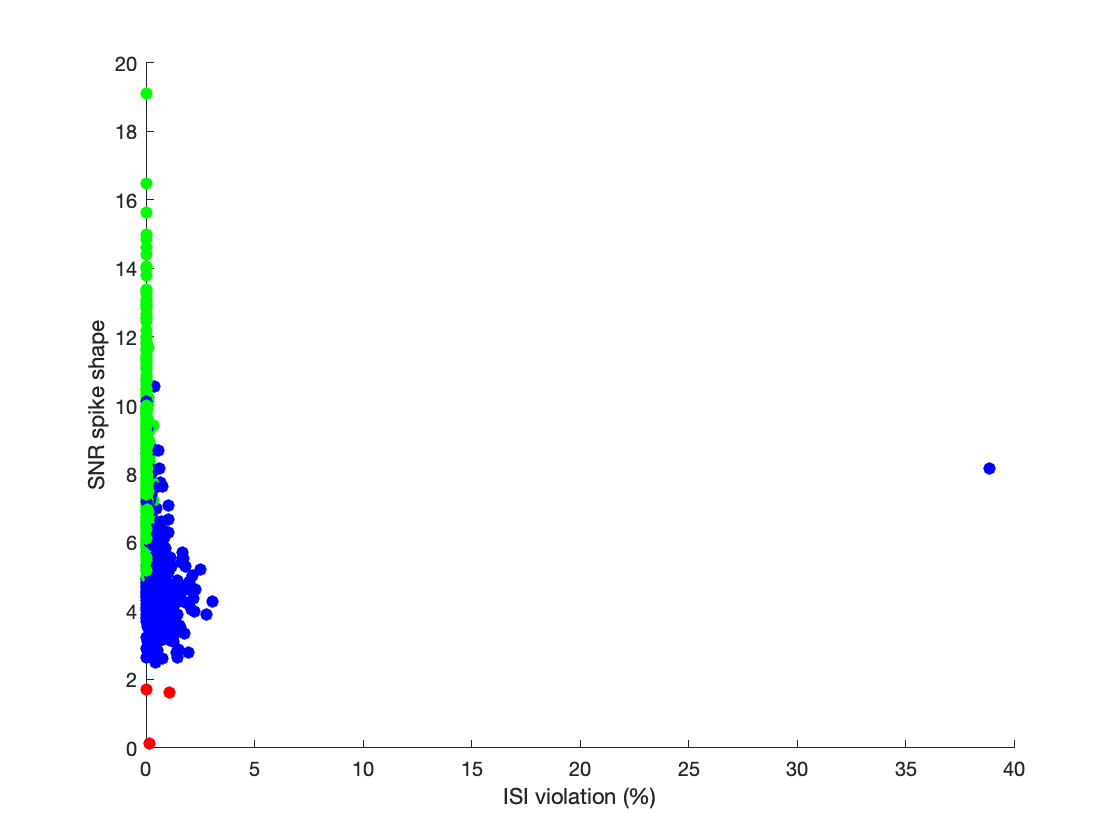


% GoodCellIndices = find(contains(SSQ, 'SS'));

% C = [contains(SSQ, 'NOISE') contains(SSQ, 'SSSU') contains(SSQ, 'SSMU')];
scatter(ISIViolation, SNR,40,C,'filled')
xlabel('ISI violation (%)')
ylabel('SNR spike shape')

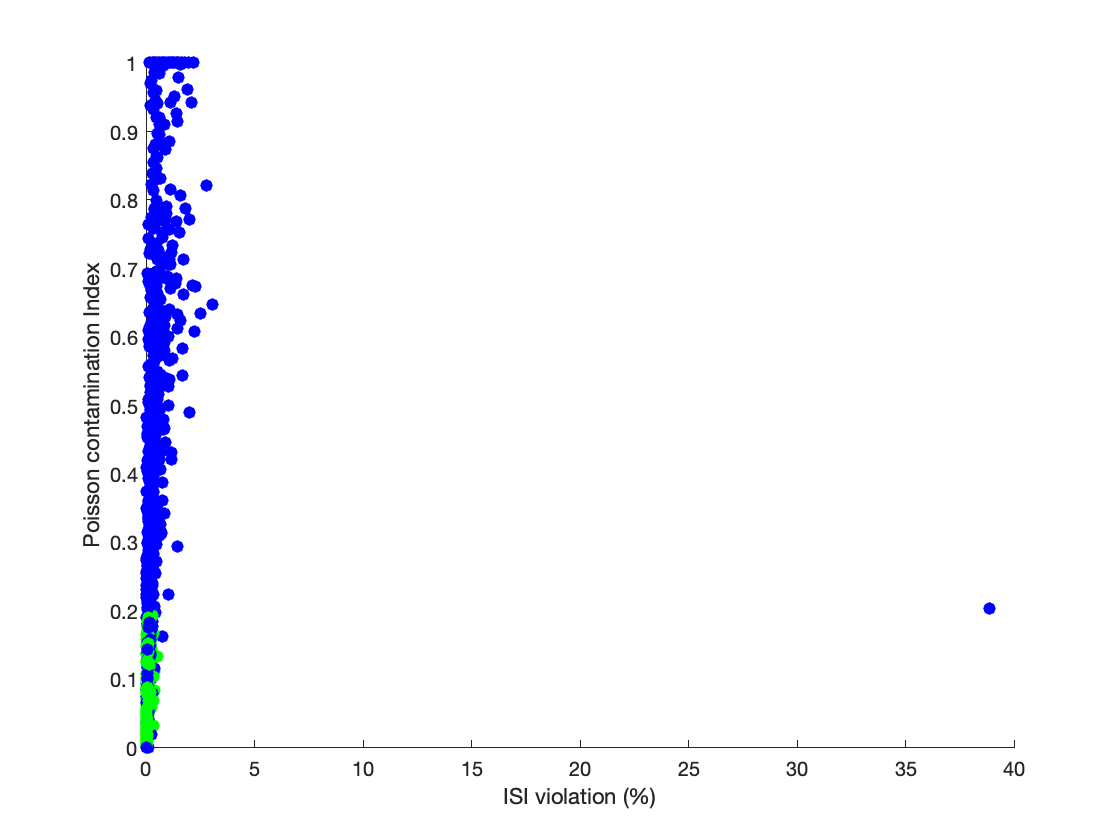

ContamInd(ContamInd>1)=1; %saturate the ContamInd, everything above 1 is just highly contaminated
scatter(ISIViolation,ContamInd, 40, C,'filled')
xlabel('ISI violation (%)')
ylabel('Poisson contamination Index')

## Gather KDE onset of all cells for Ba and Tr in Operant and Free sessions (Last run on 07/01/2022)

% gather the data
% There are weird effect of convolution at edges so Trim data 500ms
Trim = 500;
Tstart = -5000;
GoodCellIndices = sort([find(SSSU); find(SSMU)]);
GC = length(GoodCellIndices);
KDE_onset = cell(GC,9); % first column SelfBaOp, 2nd, SelfTrOp; 3rd SelfVocOp; 4th column SelfBaFr, 5th, SelfTrFr; 6th SelfVocFr; 7th column OthersBaOp, 8th, OthersTrOp; 9th OthersVocOp;
T_onset = cell(GC,2);
Tmax = nan(GC,9);
MeanKDEBaTrOp = nan(GC,1);
StdKDEBaTrOp = nan(GC,1);
MeanKDEBaTrFr = nan(GC,1);
StdKDEBaTrFr = nan(GC,1);
MeanKDEBaTrOpFr = nan(GC,1);
StdKDEBaTrOpFr = nan(GC,1);
MeanKDEAllVocOp = nan(GC,1);
StdKDEAllVocOp = nan(GC,1);
MeanKDEAllVocFr = nan(GC,1);
StdKDEAllVocFr = nan(GC,1);
MeanKDEAllVocOpFr = nan(GC,1);
StdKDEAllVocOpFr = nan(GC,1);
OperantVocalizer = nan(GC,1);
for ss=1:GC
    fprintf(1,'File %d/%d\n',ss,GC)
    Data=load(ListCells{GoodCellIndices(ss)});
    if isfield(Data,'KDE_onset') && isfield(Data.KDE_onset, 'SelfBaOp')
        if contains(ListCells{GoodCellIndices(ss)}, '65701')
            warning('Unexpected that 65701 has vocalproduction in Operant')
            keyboard
        end
        OperantVocalizer(ss) = 1;
        Tmax(ss,1) = max(Data.KDE_onset.SelfBaOp(2,(1:(end-Trim))));
        KDE_onset{ss,1} = Data.KDE_onset.SelfBaOp(1,find(Data.KDE_onset.SelfBaOp(2,:)==(Tstart+Trim)):(end-Trim));
    end
    if isfield(Data,'KDE_onset') && isfield(Data.KDE_onset, 'SelfTrOp')
        if contains(ListCells{GoodCellIndices(ss)}, '65701')
            warning('Unexpected that 65701 has vocalproduction in Operant')
            keyboard
        end
        OperantVocalizer(ss) = 1;
        Tmax(ss,2) = max(Data.KDE_onset.SelfTrOp(2,1:(end-Trim)));
        KDE_onset{ss,2} = Data.KDE_onset.SelfTrOp(1,find(Data.KDE_onset.SelfTrOp(2,:)==(Tstart+Trim)):(end-Trim));
    end
    if isfield(Data,'KDE_onset') && isfield(Data.KDE_onset, 'SelfVocOp')
        if contains(ListCells{GoodCellIndices(ss)}, '65701')
            warning('Unexpected that 65701 has vocalproduction in Operant')
            keyboard
        end
        OperantVocalizer(ss) = 1;
        Tmax(ss,3) = max(Data.KDE_onset.SelfVocOp(2,1:(end-Trim)));
        KDE_onset{ss,3} = Data.KDE_onset.SelfVocOp(1,find(Data.KDE_onset.SelfVocOp(2,:)==(Tstart+Trim)):(end-Trim));
        MeanKDEAllVocOp(ss) = nanmean(KDE_onset{ss,3}); 
        StdKDEAllVocOp(ss) = nanstd(KDE_onset{ss,3}); 
    end
    
    if isfield(Data,'KDE_onset') && isfield(Data.KDE_onset, 'SelfBaFr')
        Tmax(ss,4) = max(Data.KDE_onset.SelfBaFr(2,1:(end-Trim)));
        KDE_onset{ss,4} = Data.KDE_onset.SelfBaFr(1,find(Data.KDE_onset.SelfBaFr(2,:)==(Tstart+Trim)):(end-Trim));
    end
    if isfield(Data,'KDE_onset') && isfield(Data.KDE_onset, 'SelfTrFr')
        Tmax(ss,5) = max(Data.KDE_onset.SelfTrFr(2,1:(end-Trim)));
        KDE_onset{ss,5} = Data.KDE_onset.SelfTrFr(1,find(Data.KDE_onset.SelfTrFr(2,:)==(Tstart+Trim)):(end-Trim));
    end
    if isfield(Data,'KDE_onset') && isfield(Data.KDE_onset, 'SelfVocFr')
        Tmax(ss,6) = max(Data.KDE_onset.SelfVocFr(2,1:(end-Trim)));
        KDE_onset{ss,6} = Data.KDE_onset.SelfVocFr(1,find(Data.KDE_onset.SelfVocFr(2,:)==(Tstart+Trim)):(end-Trim));
        MeanKDEAllVocFr(ss) = nanmean(KDE_onset{ss,6}); 
        StdKDEAllVocFr(ss) = nanstd(KDE_onset{ss,6}); 
    end
    MeanKDEBaTrFr(ss) = nanmean([KDE_onset{ss,4} KDE_onset{ss,5}]); 
    StdKDEBaTrFr(ss) = nanstd([KDE_onset{ss,4} KDE_onset{ss,5}]); 
    MeanKDEBaTrOpFr(ss) = nanmean([KDE_onset{ss,4} KDE_onset{ss,5} KDE_onset{ss,1} KDE_onset{ss,2}]); 
    StdKDEBaTrOpFr(ss) = nanstd([KDE_onset{ss,4} KDE_onset{ss,5} KDE_onset{ss,1} KDE_onset{ss,2}]);
    MeanKDEAllVocOpFr(ss) = nanmean([KDE_onset{ss,3} KDE_onset{ss,6}]); 
    StdKDEAllVocOpFr(ss) = nanstd([KDE_onset{ss,3} KDE_onset{ss,6}]); 

    if isfield(Data,'KDE_onset') && isfield(Data.KDE_onset, 'OthersBaOp')
        if contains(ListCells{GoodCellIndices(ss)}, '59834') || contains(ListCells{GoodCellIndices(ss)}, '11689')
            warning('Unexpected that 59834 or 11689 has vocal perception in Operant')
            keyboard
        end
        OperantVocalizer(ss) = 0;
        Tmax(ss,7) = max(Data.KDE_onset.OthersBaOp(2,(1:(end-Trim))));
        KDE_onset{ss,7} = Data.KDE_onset.OthersBaOp(1,find(Data.KDE_onset.OthersBaOp(2,:)==(Tstart+Trim)):(end-Trim));
    end
    if isfield(Data,'KDE_onset') && isfield(Data.KDE_onset, 'OthersTrOp')
        if contains(ListCells{GoodCellIndices(ss)}, '59834') || contains(ListCells{GoodCellIndices(ss)}, '11689')
            warning('Unexpected that 59834 or 11689 has vocal perception in Operant')
            keyboard
        end
        OperantVocalizer(ss) = 0;
        Tmax(ss,8) = max(Data.KDE_onset.OthersTrOp(2,1:(end-Trim)));
        KDE_onset{ss,8} = Data.KDE_onset.OthersTrOp(1,find(Data.KDE_onset.OthersTrOp(2,:)==(Tstart+Trim)):(end-Trim));
    end
    if isfield(Data,'KDE_onset') && isfield(Data.KDE_onset, 'OthersVocOp')
        if contains(ListCells{GoodCellIndices(ss)}, '59834') || contains(ListCells{GoodCellIndices(ss)}, '11689')
            warning('Unexpected that 59834 or 11689 has vocal perception in Operant')
            keyboard
        end
        OperantVocalizer(ss) = 0;
        Tmax(ss,9) = max(Data.KDE_onset.OthersVocOp(2,1:(end-Trim)));
        KDE_onset{ss,9} = Data.KDE_onset.OthersVocOp(1,find(Data.KDE_onset.OthersVocOp(2,:)==(Tstart+Trim)):(end-Trim));
        MeanKDEAllVocOp(ss) = nanmean(KDE_onset{ss,9}); 
        StdKDEAllVocOp(ss) = nanstd(KDE_onset{ss,9}); 
    end
    if OperantVocalizer(ss)
        MeanKDEBaTrOp(ss) = nanmean([KDE_onset{ss,1} KDE_onset{ss,2}]); 
        StdKDEBaTrOp(ss) = nanstd([KDE_onset{ss,1} KDE_onset{ss,2}]); 
    else
        MeanKDEBaTrOp(ss) = nanmean([KDE_onset{ss,7} KDE_onset{ss,8}]); 
        StdKDEBaTrOp(ss) = nanstd([KDE_onset{ss,7} KDE_onset{ss,8}]); 
    end

end

File 1/1174
File 2/1174
File 3/1174
File 4/1174
File 5/1174
File 6/1174
File 7/1174
File 8/1174
File 9/1174
File 10/1174
File 11/1174
File 12/1174
File 13/1174
File 14/1174
File 15/1174
File 16/1174
File 17/1174
File 18/1174
File 19/1174
File 20/1174
File 21/1174
File 22/1174
File 23/1174
File 24/1174
File 25/1174
File 26/1174
File 27/1174
File 28/1174
File 29/1174
File 30/1174
File 31/1174
File 32/1174
File 33/1174
File 34/1174
File 35/1174
File 36/1174
File 37/1174
File 38/1174
File 39/1174
File 40/1174
File 41/1174
File 42/1174
File 43/1174
File 44/1174
File 45/1174
File 46/1174
File 47/1174
File 48/1174
File 49/1174
File 50/1174
File 51/1174
File 52/1174
File 53/1174
File 54/1174
File 55/1174
File 56/1174
File 57/1174
File 58/1174
File 59/1174
File 60/1174
File 61/1174
File 62/1174
File 63/1174
File 64/1174
File 65/1174
File 66/1174
File 67/1174
File 68/1174
File 69/1174
File 70/1174
File 71/1174
File 72/1174
File 73/1174
File 74/1174
File 75/1174
File 76/1174
File 77/1174
File 78/

save(fullfile(Path2AllData,'population_PCA_GLM_data.mat'), 'SSQ','SNR','ContamInd', 'ISIViolation', 'SubjID','SSSU', 'SSMU', 'ListCells','GoodCellIndices', 'KDE_onset','T_onset', 'Tmax', 'MeanKDEBaTrOp', 'StdKDEBaTrOp','StdKDEBaTrFr','MeanKDEBaTrFr','MeanKDEBaTrOpFr', 'StdKDEBaTrOpFr','MeanKDEAllVocOp','StdKDEAllVocOp','MeanKDEAllVocFr','StdKDEAllVocFr', 'MeanKDEAllVocOpFr','StdKDEAllVocOpFr','OperantVocalizer')

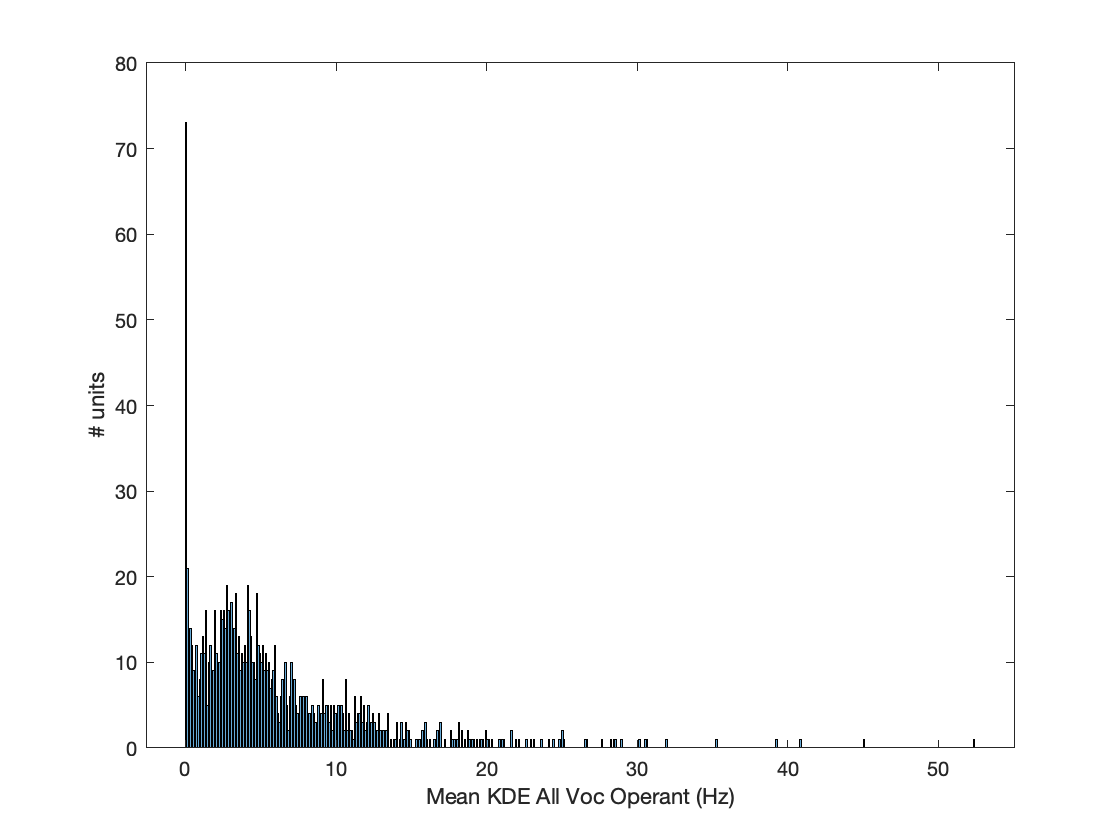

% Explore the average spike rates and get rid of non active cells?
histogram(MeanKDEAllVocOp,'BinWidth',0.1)
xlabel('Mean KDE All Voc Operant (Hz)')
ylabel('# units')
hold off

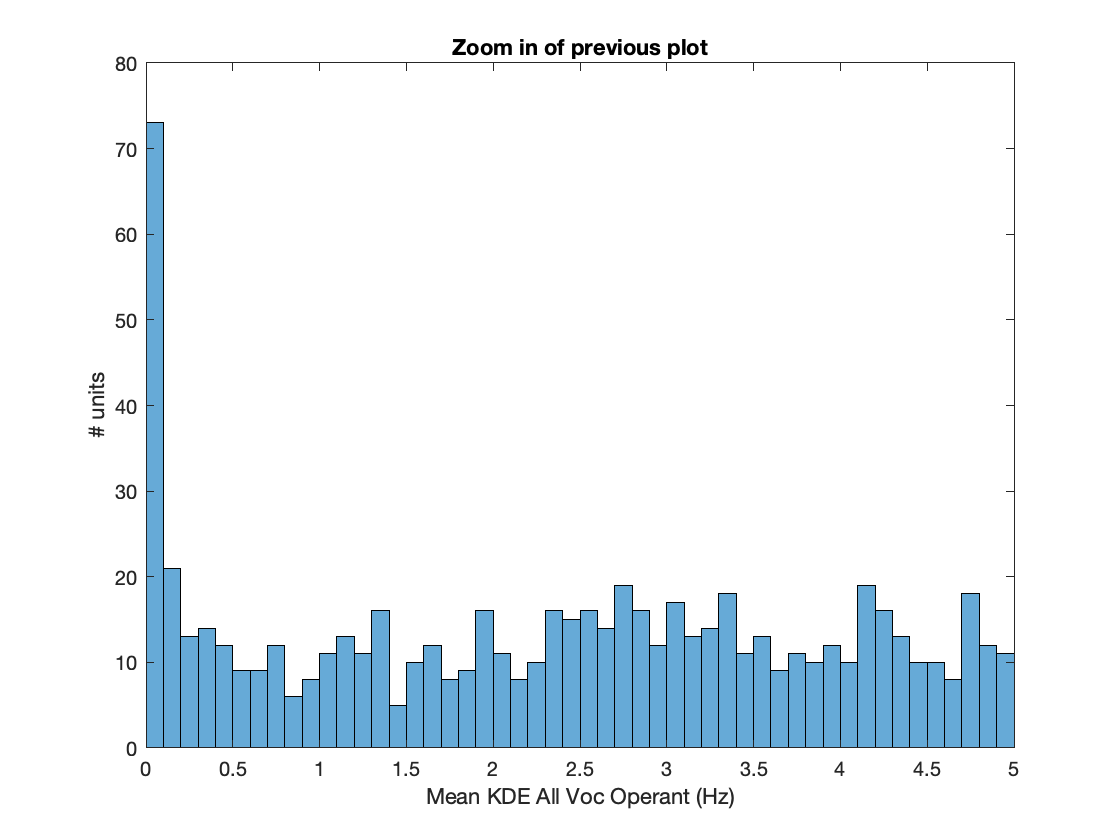

histogram(MeanKDEAllVocOp,'BinWidth',0.1)
xlabel('Mean KDE All Voc Operant (Hz)')
ylabel('# units')
title('Zoom in of previous plot')
xlim([0 5])
hold off

ActiveCells01 = find(MeanKDEAllVocOp>0.1);
fprintf(1,'Number of active cells in operant session: %d/%d',length(ActiveCells01), length(MeanKDEAllVocOp))

Number of active cells in operant session: 1101/1174

### Let's try a PCA on the ZS but feeding independently BA and Tr

% Data loader to skip previous cells
load(fullfile(Path2AllData,'population_PCA_GLM_data.mat'), 'ListCells', 'GoodCellIndices','MeanKDEAllVocOp', 'Tmax','MeanKDEBaTrOp','StdKDEBaTrOp')

% Variables reinitialisation to skip previous steps
Trim = 500;
Tstart = -5000;

% Trim the data of active cells in time and create a matrix of all the
% z-scored KDE Tr and Ba Op For both Hearing and vocalizing bats (last run
% on 07/01/2022)

% Cells that are either SMU or SSU
ListCellsG = ListCells(GoodCellIndices);
% Active Cells
ActiveCells01 = MeanKDEAllVocOp>0.1;
ListCellsGA = ListCellsG(ActiveCells01);
% select cells that are either from vocalizer or listener of either Trills and non-trills during operant and that have a minimum average rate over all voc of 0.1Hz
BaorTr_0ind = logical((~isnan(Tmax(:,1)) + ~isnan(Tmax(:,7)) + ~isnan(Tmax(:,2)) + ~isnan(Tmax(:,8))).* (~isnan(MeanKDEBaTrOp)).*(MeanKDEAllVocOp>0.1)); 
BaorTr_Ind = find(BaorTr_0ind);
% select cells that are from vocalizer or Listener of either Trills and non-trills during operant and that have a minimum average rate over all voc of 0.1Hz
ListCellsGAOp = ListCellsG(BaorTr_0ind);

fprintf(1, 'Active cells defined as having a minimum time and vocalization average rate of 0.1Hz: %d/%d', sum(ActiveCells01), length(MeanKDEAllVocOp))

Active cells defined as having a minimum time and vocalization average rate of 0.1Hz: 1101/1174

fprintf('The PCA on time varying rate during Operant can be performed on the data of %d/%d\n',sum(BaorTr_0ind),length(ActiveCells01))

The PCA on time varying rate during Operant can be performed on the data of 1101/1174



% find the minimum duration of the KDE for all cells
TAll = length(Tstart+Trim:min([Tmax(:,1); Tmax(:,2); Tmax(:,7); Tmax(:,8)]))

TAll = 9084

KDE_onset_Mat_nTr = nan(sum(BaorTr_0ind),TAll);
KDE_onset_Mat_Tr = nan(sum(BaorTr_0ind),TAll);
for ss=1:sum(BaorTr_0ind)
    fprintf(1,'File %d/%d: %s\n',ss,sum(BaorTr_0ind), ListCellsGAOp{ss})
    if OperantVocalizer(BaorTr_Ind(ss))
        if ~isempty(KDE_onset{BaorTr_Ind(ss),1})
            KDE_onset_Mat_nTr(ss,:) = (KDE_onset{BaorTr_Ind(ss),1}(1:TAll) -MeanKDEBaTrOp(BaorTr_Ind(ss)))./StdKDEBaTrOp(BaorTr_Ind(ss));
        end 
        if ~isempty(KDE_onset{BaorTr_Ind(ss),2})
            KDE_onset_Mat_Tr(ss,:) = (KDE_onset{BaorTr_Ind(ss),2}(1:TAll) -MeanKDEBaTrOp(BaorTr_Ind(ss)))./StdKDEBaTrOp(BaorTr_Ind(ss));
        end
    else
        if ~isempty(KDE_onset{BaorTr_Ind(ss),7})
            KDE_onset_Mat_nTr(ss,:) = (KDE_onset{BaorTr_Ind(ss),7}(1:TAll) -MeanKDEBaTrOp(BaorTr_Ind(ss)))./StdKDEBaTrOp(BaorTr_Ind(ss));
        end
        if ~isempty(KDE_onset{BaorTr_Ind(ss),8})
            KDE_onset_Mat_Tr(ss,:) = (KDE_onset{BaorTr_Ind(ss),8}(1:TAll) -MeanKDEBaTrOp(BaorTr_Ind(ss)))./StdKDEBaTrOp(BaorTr_Ind(ss));
        end
    end
end

File 1/1101: /Volumes/JulieE8T/LMCResults/59834_20190604_SSS_3-109.mat
File 2/1101: /Volumes/JulieE8T/LMCResults/59834_20190604_SSS_3-111.mat
File 3/1101: /Volumes/JulieE8T/LMCResults/59834_20190604_SSS_3-191.mat
File 4/1101: /Volumes/JulieE8T/LMCResults/59834_20190604_SSS_4-193.mat
File 5/1101: /Volumes/JulieE8T/LMCResults/59834_20190604_SSS_4-197.mat
File 6/1101: /Volumes/JulieE8T/LMCResults/59834_20190604_SSM_1-201.mat
File 7/1101: /Volumes/JulieE8T/LMCResults/59834_20190604_SSM_1-206.mat
File 8/1101: /Volumes/JulieE8T/LMCResults/59834_20190604_SSM_1-233.mat
File 9/1101: /Volumes/JulieE8T/LMCResults/59834_20190604_SSM_2-208.mat
File 10/1101: /Volumes/JulieE8T/LMCResults/59834_20190604_SSM_3-115.mat
File 11/1101: /Volumes/JulieE8T/LMCResults/59834_20190604_SSM_3-213.mat
File 12/1101: /Volumes/JulieE8T/LMCResults/59834_20190604_SSM_3-229.mat
File 13/1101: /Volumes/JulieE8T/LMCResults/59834_20190604_SSM_4-135.mat
File 14/1101: /Volumes/JulieE8T/LMCResults/59834_20190604_SSM_4-241.mat
F

save(fullfile(Path2AllData,'population_PCA_GLM_data.mat'), 'KDE_onset_Mat_nTr','KDE_onset_Mat_Tr', 'BaorTr_Ind','BaorTr_0ind','ListCellsGAOp', '-append')

% run PCA on the ZS of the operant KDE
NanTr = isnan(KDE_onset_Mat_Tr(:,1));
NannTr = isnan(KDE_onset_Mat_nTr(:,1));
fprintf(1,'%d cells are represented by 2 entries (Tr and nonTr KDE)\n', sum((~NanTr) .* (~NannTr)));

646 cells are represented by 2 entries (Tr and nonTr KDE)


fprintf(1,'%d cells are represented by only 1 entry for Tr KDE)\n', sum((~NanTr) .* (NannTr)));

401 cells are represented by only 1 entry for Tr KDE)


fprintf(1,'%d cells are represented by only 1 entry for nonTr KDE)\n', sum((NanTr) .* (~NannTr)));

54 cells are represented by only 1 entry for nonTr KDE)


[PC,Score,~, ~, VarExpl,~] = pca([KDE_onset_Mat_Tr(~NanTr,:); KDE_onset_Mat_nTr(~NannTr,:)]);

ListCellsGAOpScore = {ListCellsGAOp(~NanTr); ListCellsGAOp(~NannTr)};
CellID = [1:length(ListCellsGAOp) 1:length(ListCellsGAOp)]';
CellID = CellID([~NanTr; ~NannTr]); % Easily retrieve name of cells in Score by ListCellsGAOpScore = ListCellsGAOp(CellID);

% Plot the cumulative explained variance as a function of # PCs
plot(cumsum(VarExpl), 'LineWidth',2);xlabel('#PC');ylabel('Proportion variance explained by PCA)'); xlim([0 30])
title('PCA on KDE of Trill and non-Trill separately fed')

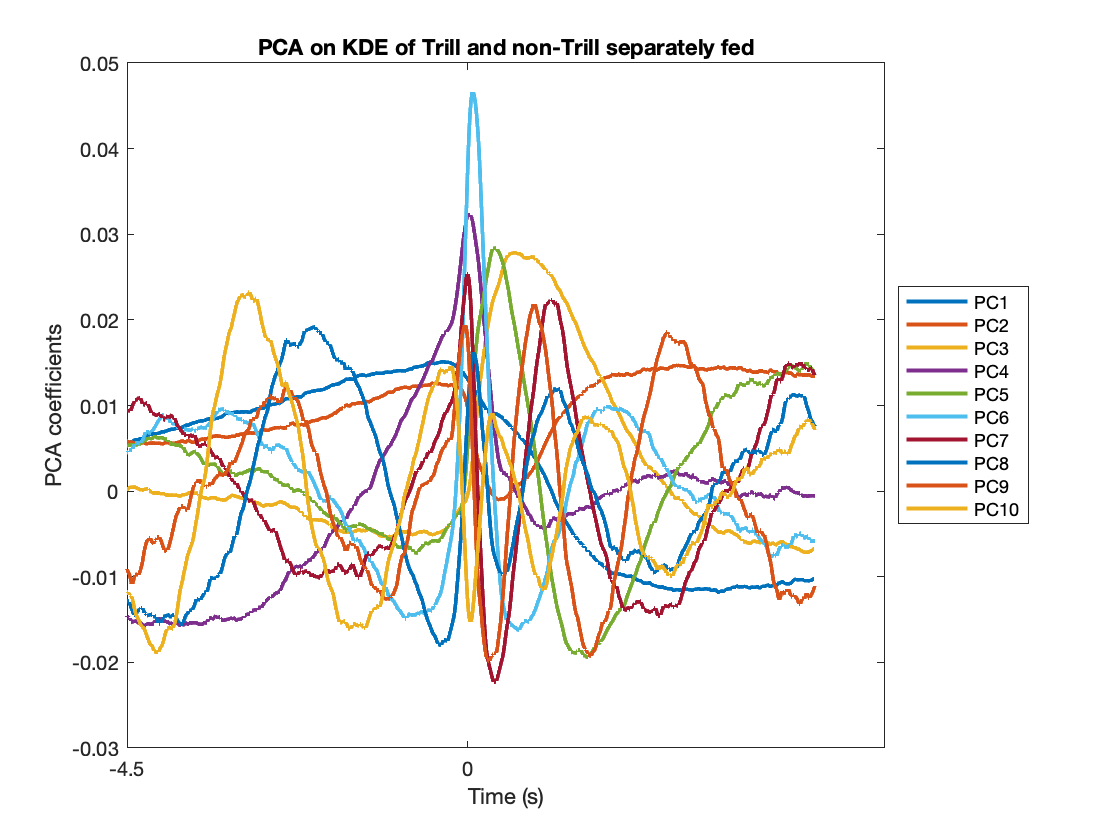

% Plot the first PC shapes
plot(PC(:,1), 'LineWidth',2);hold on;plot(PC(:,2), 'LineWidth',2);plot(PC(:,3), 'LineWidth',2);plot(PC(:,4), 'LineWidth',2);plot(PC(:,5), 'LineWidth',2);plot(PC(:,6), 'LineWidth',2);plot(PC(:,7), 'LineWidth',2);plot(PC(:,8), 'LineWidth',2);plot(PC(:,9), 'LineWidth',2);plot(PC(:,10), 'LineWidth',2);legend('PC1', 'PC2','PC3', 'PC4', 'PC5', 'PC6','PC7','PC8','PC9','PC10', 'Location', 'EastOutside'); ylabel('PCA coefficients');xlabel('Time (s)');xticks([1 -(Tstart+Trim)]);xticklabels([(Tstart+Trim)/10^3 0]);title('PCA on KDE of Trill and non-Trill separately fed')
hold off

% Plot swarmplots of PC weights (scores) with color coded if a cell is from a
% vocalizer or listener
NanTr = isnan(KDE_onset_Mat_Tr(:,1));
NannTr = isnan(KDE_onset_Mat_nTr(:,1));
OperantVocalizerCells01 = OperantVocalizer(BaorTr_0ind);
OV_cells = [OperantVocalizerCells01(~NanTr); OperantVocalizerCells01(~NannTr)]; % Vocalizer cells=1
OnT_cells = logical([zeros(sum(~NanTr),1); ones(sum(~NannTr),1)]); % Mesh on =1 <-> NonTrills=1
OVT_cells = logical(OV_cells .* (~OnT_cells));
OVnT_cells = logical(OV_cells .* OnT_cells);
OLT_cells = logical((~OV_cells) .* (~OnT_cells));
OLnT_cells = logical((~OV_cells) .* OnT_cells);
ColPC = get(groot, 'DefaultAxesColorOrder');
ScatterMarkerSz=30;
MeanMarkerSize=14;
NPC=15;
LMEpValVL = nan(NPC,1);
LMEpValTnT = nan(NPC,1);
LMEpValnull = nan(NPC,1);
LMEpValInt = nan(NPC,1);
LMpValVL_Trill = nan(NPC,1);
LMpValVL_nonTrill = nan(NPC,1);
LMCoeffVL_Trill = nan(NPC,1);
LMCoeffVL_nonTrill = nan(NPC,1);
for n=1:NPC
    swarmchart((5*n-3)*ones(sum(OVT_cells),1),Score(OVT_cells,n),ScatterMarkerSz,ColPC(2,:),'o','filled','MarkerFaceAlpha',0.5,'MarkerEdgeAlpha',0.5)
    hold on
    swarmchart((5*n-2)*ones(sum(OLT_cells),1),Score(OLT_cells,n),ScatterMarkerSz,ColPC(1,:),'o','filled','MarkerFaceAlpha',0.5,'MarkerEdgeAlpha',0.5)
    hold on
    swarmchart((5*n-1)*ones(sum(OVnT_cells),1),Score(OVnT_cells,n),ScatterMarkerSz,ColPC(3,:),'o','filled','MarkerFaceAlpha',0.5,'MarkerEdgeAlpha',0.5)
    hold on
    swarmchart((5*n)*ones(sum(OLnT_cells),1),Score(OLnT_cells,n),ScatterMarkerSz,ColPC(5,:),'o','filled','MarkerFaceAlpha',0.5,'MarkerEdgeAlpha',0.5)
    hold on
    if n==1
        legend({'Vocalizer Trills', 'Listener Trills', 'Vocalizer non-Trills', 'Listener non-Trills'})
        legend('Location', 'SouthEast','AutoUpdate','off')
    end
    errorbar((5*n-3),nanmean(Score(OVT_cells,n)),nanstd(Score(OVT_cells,n))/sum(OVT_cells)^0.5, 'dk','MarkerSize',MeanMarkerSize,'MarkerFaceColor',ColPC(2,:))
    hold on
    errorbar((5*n-2),nanmean(Score(OLT_cells,n)),nanstd(Score(OLT_cells,n))/sum(OLT_cells)^0.5, 'dk','MarkerSize',MeanMarkerSize,'MarkerFaceColor',ColPC(1,:))
    hold on
    errorbar((5*n-1),nanmean(Score(OVnT_cells,n)),nanstd(Score(OVnT_cells,n))/sum(OVnT_cells)^0.5, 'dk','MarkerSize',MeanMarkerSize,'MarkerFaceColor',ColPC(3,:))
    hold on
    errorbar((5*n),nanmean(Score(OLnT_cells,n)),nanstd(Score(OLnT_cells,n))/sum(OLnT_cells)^0.5, 'dk','MarkerSize',MeanMarkerSize,'MarkerFaceColor',ColPC(5,:))
    hold on
    Tbl =  table(Score(:,n), logical(OV_cells), logical(~OnT_cells),[ListCellsGAOp(~NanTr); ListCellsGAOp(~NannTr)], 'VariableNames', {'PCScore', 'VorL','TorNT','CellID'});
    lmefull = fitlme(Tbl, 'PCScore~VorL*TorNT+(1|CellID)');
    lmeInt = fitlme(Tbl, 'PCScore~VorL+TorNT+(1|CellID)');
    lmeVL = fitlme(Tbl, 'PCScore~TorNT+(1|CellID)');
    lmeTnT = fitlme(Tbl, 'PCScore~VorL+(1|CellID)');
    lmenull = fitlme(Tbl, 'PCScore~1+(1|CellID)');
    TestLMEnull=compare(lmenull, lmefull);
    TestLMEVL = compare(lmeVL,lmefull);
    TestLMETnT = compare(lmeTnT,lmefull);
    TestLMEInt = compare(lmeInt, lmefull);
    LMEpValVL(n) = TestLMEVL.pValue(2);
    LMEpValnull(n) = TestLMEnull.pValue(2);
    LMEpValTnT(n) = TestLMETnT.pValue(2);
    LMEpValInt(n) = TestLMEInt.pValue(2);
    if LMEpValVL(n)<0.01
        plot((5*n-3), 125,'r*','MarkerSize',15);
        fprintf(1,'\n\n\n**********PC%d: Effect of Vocalizer vs Listener\n***********', n)
        lmefull
        fprintf(1, 'Effect of VorL:')
        LMEpValVL(n)
        fprintf('Effect of Interaction:')
        LMEpValInt(n)
        % run a model per call type
        TblTrill = table(Score(~OnT_cells,n), logical(OV_cells(~OnT_cells)), 'VariableNames', {'PCScore', 'VorL'});
        LmTrill = fitlm(TblTrill, 'PCScore~VorL')
        ATrill = LmTrill.anova;
        LMpValVL_Trill(n) = ATrill.pValue(1);
        LMCoeffVL_Trill(n) = LmTrill.Coefficients.Estimate(2);
        TblnonTrill = table(Score(OnT_cells,n), logical(OV_cells(OnT_cells)), 'VariableNames', {'PCScore', 'VorL'});
        LmnonTrill = fitlm(TblnonTrill, 'PCScore~VorL')
        AnonTrill = LmnonTrill.anova;
        LMpValVL_nonTrill(n) = AnonTrill.pValue(1);
        LMCoeffVL_nonTrill(n) = LmnonTrill.Coefficients.Estimate(2);
    end
    if LMEpValTnT(n)<0.01
        fprintf(1,'\n\n\n**********PC%d: Effect of Trill vs non-Trill\n***********', n)
        plot((5*n-1), 125,'b*','MarkerSize',15);
        fprintf(1, 'Effect of TorNT:')
        LMEpValTnT(n)
        fprintf('Effect of Interaction:')
        LMEpValInt(n)
    end
    if LMEpValInt(n)<0.01
        plot((5*n-2), 125,'g*','MarkerSize',15);
        if isnan(LMpValVL_Trill(n))
            % run a model per call type
            TblTrill = table(Score(~OnT_cells,n), logical(OV_cells(~OnT_cells)), 'VariableNames', {'PCScore', 'VorL'});
            fprintf(1, '\nEffect of VorL within Trills:\n')
            LmTrill = fitlm(TblTrill, 'PCScore~VorL')
            ATrill = LmTrill.anova;
            LMpValVL_Trill(n) = ATrill.pValue(1);
            LMCoeffVL_Trill(n) = LmTrill.Coefficients.Estimate(2);
            TblnonTrill = table(Score(OnT_cells,n), logical(OV_cells(OnT_cells)), 'VariableNames', {'PCScore', 'VorL'});
            fprintf(1, '\nEffect of VorL within non-Trills\n:')
            LmnonTrill = fitlm(TblnonTrill, 'PCScore~VorL')
            AnonTrill = LmnonTrill.anova;
            LMpValVL_nonTrill(n) = AnonTrill.pValue(1);
            LMCoeffVL_nonTrill(n) = LmnonTrill.Coefficients.Estimate(2);
        end

    end
    if LMEpValnull(n)<0.01
        plot((5*n-1.5), 140,'k*','MarkerSize',15);
    end


end




**********PC1: Effect of Trill vs non-Trill
***********

Effect of TorNT:

ans = 0

Effect of Interaction:

ans = 0.0073


Effect of VorL within Trills:


LmTrill = Linear regression model:
    PCScore ~ 1 + VorL

Estimated Coefficients:
                   Estimate      SE       tStat       pValue  
                   ________    ______    _______    __________

    (Intercept)    -8.8236     2.1841    -4.0398    5.7404e-05
    VorL_1          -4.925     2.9759     -1.655      0.098228


Number of observations: 1047, Error degrees of freedom: 1045
Root Mean Squared Error: 48
R-squared: 0.00261,  Adjusted R-Squared: 0.00166
F-statistic vs. constant model: 2.74, p-value = 0.0982


Effect of VorL within non-Trills
:

LmnonTrill = Linear regression model:
    PCScore ~ 1 + VorL

Estimated Coefficients:
                   Estimate      SE      tStat       pValue  
                   ________    ______    ______    __________

    (Intercept)     12.394      3.551    3.4902    0.00051292
    VorL_1           8.435     4.7212    1.7866      0.074433


Number of observations: 700, Error degrees of freedom: 698
Root Mean Squared Error: 61.9
R-squared: 0.00455,  Adjusted R-Squared: 0.00313
F-statistic vs. constant model: 3.19, p-value = 0.0744




**********PC2: Effect of Trill vs non-Trill
***********

Effect of TorNT:

ans = 1.1371e-10

Effect of Interaction:

ans = 0.1037




**********PC3: Effect of Vocalizer vs Listener
***********

lmefull = Linear mixed-effects model fit by ML

Model information:
    Number of observations            1747
    Fixed effects coefficients           4
    Random effects coefficients       1101
    Covariance parameters                2

Formula:
    PCScore ~ 1 + VorL*TorNT + (1 | CellID)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    16913    16946    -8450.6          16901   

Fixed effects coefficients (95% CIs):
    Name                      Estimate    SE        tStat      DF      pValue        Lower      Upper  
    {'(Intercept)'   }        -6.9928     1.7497    -3.9966    1743    6.6935e-05    -10.424    -3.5611
    {'VorL_1'        }         8.8545     2.3288     3.8021    1743    0.00014841     4.2869     13.422
    {'TorNT_1'       }         5.6541     1.9963     2.8323    1743      0.004675     1.7387     9.5695
    {'VorL_1:TorNT_1'}        -4.0466     2.6731

Effect of VorL:

ans = 1.7462e-04

Effect of Interaction:

ans = 0.1321

LmTrill = Linear regression model:
    PCScore ~ 1 + VorL

Estimated Coefficients:
                   Estimate      SE       tStat       pValue  
                   ________    ______    ________    _________

    (Intercept)    -1.0239     1.3585    -0.75375      0.45117
    VorL_1          4.8039     1.8509      2.5954    0.0095793


Number of observations: 1047, Error degrees of freedom: 1045
Root Mean Squared Error: 29.9
R-squared: 0.0064,  Adjusted R-Squared: 0.00545
F-statistic vs. constant model: 6.74, p-value = 0.00958

LmnonTrill = Linear regression model:
    PCScore ~ 1 + VorL

Estimated Coefficients:
                   Estimate      SE       tStat       pValue  
                   ________    ______    _______    __________

    (Intercept)     -6.546     1.8669    -3.5064    0.00048323
    VorL_1          7.4366     2.4821     2.9961     0.0028312


Number of observations: 700, Error degrees of freedom: 698
Root Mean Squared Error: 32.5
R-squared: 0.0127,  Adjusted R-Squared: 0.0113
F-statistic vs. constant model: 8.98, p-value = 0.00283




**********PC4: Effect of Vocalizer vs Listener
***********

lmefull = Linear mixed-effects model fit by ML

Model information:
    Number of observations            1747
    Fixed effects coefficients           4
    Random effects coefficients       1101
    Covariance parameters                2

Formula:
    PCScore ~ 1 + VorL*TorNT + (1 | CellID)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    16089    16122    -8038.4          16077   

Fixed effects coefficients (95% CIs):
    Name                      Estimate    SE        tStat      DF      pValue        Lower      Upper  
    {'(Intercept)'   }        -2.0081     1.3823    -1.4528    1743       0.14646    -4.7192    0.70292
    {'VorL_1'        }         14.675     1.8381     7.9833    1743    2.5613e-15     11.069      18.28
    {'TorNT_1'       }        -2.4725     1.6835    -1.4686    1743       0.14211    -5.7745    0.82948
    {'VorL_1:TorNT_1'}        -14.509     2.2573

Effect of VorL:

ans = 2.1427e-14

Effect of Interaction:

ans = 2.0906e-10

LmTrill = Linear regression model:
    PCScore ~ 1 + VorL

Estimated Coefficients:
                   Estimate      SE       tStat        pValue  
                   ________    ______    ________    __________

    (Intercept)     -4.4941    0.9621     -4.6712    3.3848e-06
    VorL_1         0.079749    1.3108    0.060837        0.9515


Number of observations: 1047, Error degrees of freedom: 1045
Root Mean Squared Error: 21.1
R-squared: 3.54e-06,  Adjusted R-Squared: -0.000953
F-statistic vs. constant model: 0.0037, p-value = 0.952

LmnonTrill = Linear regression model:
    PCScore ~ 1 + VorL

Estimated Coefficients:
                   Estimate      SE       tStat        pValue  
                   ________    ______    ________    __________

    (Intercept)    -1.5963      1.614    -0.98907       0.32297
    VorL_1           14.59     2.1458      6.7995    2.2571e-11


Number of observations: 700, Error degrees of freedom: 698
Root Mean Squared Error: 28.1
R-squared: 0.0621,  Adjusted R-Squared: 0.0608
F-statistic vs. constant model: 46.2, p-value = 2.26e-11




**********PC4: Effect of Trill vs non-Trill
***********

Effect of TorNT:

ans = 0

Effect of Interaction:

ans = 2.0906e-10




**********PC7: Effect of Vocalizer vs Listener
***********

lmefull = Linear mixed-effects model fit by ML

Model information:
    Number of observations            1747
    Fixed effects coefficients           4
    Random effects coefficients       1101
    Covariance parameters                2

Formula:
    PCScore ~ 1 + VorL*TorNT + (1 | CellID)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    14213    14246    -7100.5          14201   

Fixed effects coefficients (95% CIs):
    Name                      Estimate    SE         tStat      DF      pValue        Lower      Upper  
    {'(Intercept)'   }        -3.3577     0.80812     -4.155    1743     3.411e-05    -4.9427    -1.7727
    {'VorL_1'        }         6.6258      1.0744     6.1668    1743    8.6436e-10     4.5185     8.7331
    {'TorNT_1'       }         1.6441      1.0209     1.6105    1743       0.10748    -0.3582     3.6464
    {'VorL_1:TorNT_1'}        -3.9281      1

Effect of VorL:

ans = 1.0335e-10

Effect of Interaction:

ans = 0.0043

LmTrill = Linear regression model:
    PCScore ~ 1 + VorL

Estimated Coefficients:
                   Estimate      SE        tStat       pValue  
                   ________    _______    _______    __________

    (Intercept)    -1.7106     0.58116    -2.9434     0.0033178
    VorL_1          2.7034     0.79183     3.4142    0.00066432


Number of observations: 1047, Error degrees of freedom: 1045
Root Mean Squared Error: 12.8
R-squared: 0.011,  Adjusted R-Squared: 0.0101
F-statistic vs. constant model: 11.7, p-value = 0.000664

LmnonTrill = Linear regression model:
    PCScore ~ 1 + VorL

Estimated Coefficients:
                   Estimate      SE        tStat       pValue  
                   ________    _______    _______    __________

    (Intercept)    -3.3526     0.91186    -3.6767    0.00025445
    VorL_1          6.5987      1.2124     5.4429    7.2651e-08


Number of observations: 700, Error degrees of freedom: 698
Root Mean Squared Error: 15.9
R-squared: 0.0407,  Adjusted R-Squared: 0.0393
F-statistic vs. constant model: 29.6, p-value = 7.27e-08




**********PC10: Effect of Vocalizer vs Listener
***********

lmefull = Linear mixed-effects model fit by ML

Model information:
    Number of observations            1747
    Fixed effects coefficients           4
    Random effects coefficients       1101
    Covariance parameters                2

Formula:
    PCScore ~ 1 + VorL*TorNT + (1 | CellID)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    12969    13002    -6478.4          12957   

Fixed effects coefficients (95% CIs):
    Name                      Estimate    SE         tStat       DF      pValue       Lower       Upper   
    {'(Intercept)'   }          1.2134      0.566      2.1437    1743     0.032192     0.10325      2.3235
    {'VorL_1'        }         -2.3132    0.75252     -3.0739    1743    0.0021457     -3.7891    -0.83722
    {'TorNT_1'       }        -0.57827    0.72249    -0.80039    1743       0.4236     -1.9953     0.83876
    {'VorL_1:TorNT_1'}          1.25

Effect of VorL:

ans = 0.0020

Effect of Interaction:

ans = 0.1967

LmTrill = Linear regression model:
    PCScore ~ 1 + VorL

Estimated Coefficients:
                   Estimate      SE        tStat      pValue 
                   ________    _______    _______    ________

    (Intercept)    0.63509      0.4006     1.5854     0.11319
    VorL_1         -1.0608     0.54581    -1.9435    0.052225


Number of observations: 1047, Error degrees of freedom: 1045
Root Mean Squared Error: 8.8
R-squared: 0.0036,  Adjusted R-Squared: 0.00265
F-statistic vs. constant model: 3.78, p-value = 0.0522

LmnonTrill = Linear regression model:
    PCScore ~ 1 + VorL

Estimated Coefficients:
                   Estimate      SE        tStat      pValue  
                   ________    _______    _______    _________

    (Intercept)     1.2134     0.64814     1.8721     0.061617
    VorL_1         -2.3132     0.86173    -2.6843    0.0074402


Number of observations: 700, Error degrees of freedom: 698
Root Mean Squared Error: 11.3
R-squared: 0.0102,  Adjusted R-Squared: 0.0088
F-statistic vs. constant model: 7.21, p-value = 0.00744




**********PC13: Effect of Vocalizer vs Listener
***********

lmefull = Linear mixed-effects model fit by ML

Model information:
    Number of observations            1747
    Fixed effects coefficients           4
    Random effects coefficients       1101
    Covariance parameters                2

Formula:
    PCScore ~ 1 + VorL*TorNT + (1 | CellID)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    12232    12265    -6110.1          12220   

Fixed effects coefficients (95% CIs):
    Name                      Estimate    SE         tStat      DF      pValue        Lower       Upper   
    {'(Intercept)'   }         -1.1987    0.45843    -2.6149    1743     0.0090029     -2.0979    -0.29961
    {'VorL_1'        }          2.2779     0.6095     3.7373    1743    0.00019204      1.0824      3.4733
    {'TorNT_1'       }         0.36519    0.58518    0.62406    1743       0.53267    -0.78254      1.5129
    {'VorL_1:TorNT_1'}        -0.842

Effect of VorL:

ans = 1.4954e-05

Effect of Interaction:

ans = 0.2838

LmTrill = Linear regression model:
    PCScore ~ 1 + VorL

Estimated Coefficients:
                   Estimate      SE        tStat      pValue  
                   ________    _______    _______    _________

    (Intercept)    -0.83355    0.35954    -2.3184     0.020622
    VorL_1           1.4358    0.48987      2.931    0.0034519


Number of observations: 1047, Error degrees of freedom: 1045
Root Mean Squared Error: 7.9
R-squared: 0.00815,  Adjusted R-Squared: 0.0072
F-statistic vs. constant model: 8.59, p-value = 0.00345

LmnonTrill = Linear regression model:
    PCScore ~ 1 + VorL

Estimated Coefficients:
                   Estimate      SE        tStat       pValue  
                   ________    _______    _______    __________

    (Intercept)    -1.1987     0.46745    -2.5644      0.010542
    VorL_1          2.2779     0.62149     3.6652    0.00026592


Number of observations: 700, Error degrees of freedom: 698
Root Mean Squared Error: 8.15
R-squared: 0.0189,  Adjusted R-Squared: 0.0175
F-statistic vs. constant model: 13.4, p-value = 0.000266

set(gca, 'XTick', 5*(1:NPC)-1, 'XTickLabel',1:NPC)
xlabel('PC #')
ylabel('PC score')
title('Weights of PC compomenets for each cell response')
hold off

% Plot the PC shapes significant for the effect of Vocalizer/Listner in
% linear models
PCSigT = find(LMpValVL_Trill<0.01);
PCSigNT = find(LMpValVL_nonTrill<0.01);
tiledlayout(2,1)
nexttile
for n=1:length(PCSigT)
    legend('AutoUpdate',"on")
    plot(PC(:,PCSigT(n)), 'LineWidth',2, 'DisplayName',sprintf('PC%d',PCSigT(n)) );
    hold on;
end
ylabel('PCA coefficients ');
xlabel('Time (s)');
xticks([1 -(Tstart+Trim)]);xticklabels([(Tstart+Trim)/10^3 0]);
title('PCA on KDE of Trill and non-Trill separately fed, signif. PC bw L/V for Trills')
hold off
nexttile
for n=1:length(PCSigNT)
    legend('AutoUpdate',"on")
    plot(PC(:,PCSigNT(n)), 'LineWidth',2, 'DisplayName',sprintf('PC%d',PCSigNT(n)) );
    hold on;
end
ylabel('PCA coefficients');
xlabel('Time (s)');
xticks([1 -(Tstart+Trim)]);xticklabels([(Tstart+Trim)/10^3 0]);
title('PCA on KDE of Trill and non-Trill separately fed, signif. PC bw L/V for non Trills')
hold off

% Now we want to model the distribution of responses in the PC space for
% listener neurons
% first let's plot the scatters of that distribution

figure()
scatter(Score(OLT_cells,PCSigT(1)),Score(OLT_cells,PCSigT(2)),'ro', 'filled')
hold on
scatter(Score(OLnT_cells,PCSigT(1)),Score(OLnT_cells,PCSigT(2)), 'bo', 'filled')
legend({'Trill', 'non-Trill'})
title('Listener cells; PC VorL Trills')
xlabel(sprintf('Trill PC%d',PCSigT(1)))
ylabel(sprintf('Trill PC%d',PCSigT(2)))
hold off

scatter(Score(OLT_cells,PCSigT(1)),Score(OLT_cells,PCSigT(3)),'ro', 'filled')
hold on
scatter(Score(OLnT_cells,PCSigT(1)),Score(OLnT_cells,PCSigT(3)), 'bo', 'filled')
legend({'Trill', 'non-Trill'})
title('Listener cells PC VorL Trills')
xlabel(sprintf('Trill PC%d',PCSigT(1)))
ylabel(sprintf('Trill PC%d',PCSigT(3)))
hold off


scatter(Score(OLT_cells,PCSigNT(1)),Score(OLT_cells,PCSigNT(2)),'ro', 'filled')
hold on
scatter(Score(OLnT_cells,PCSigNT(1)),Score(OLnT_cells,PCSigNT(2)), 'bo', 'filled')
legend({'Trill', 'non-Trill'})
title('Listener cells PC VorL non-Trills')
xlabel(sprintf('non-Trill PC%d',PCSigNT(1)))
ylabel(sprintf('non-Trill PC%d',PCSigNT(2)))
hold off

scatter(Score(OLT_cells,PCSigNT(1)),Score(OLT_cells,PCSigNT(3)),'ro', 'filled')
hold on
scatter(Score(OLnT_cells,PCSigNT(1)),Score(OLnT_cells,PCSigNT(3)), 'bo', 'filled')
legend({'Trill', 'non-Trill'})
title('Listener cells PC VorL non-Trills')
xlabel(sprintf('non-Trill PC%d',PCSigNT(1)))
ylabel(sprintf('non-Trill PC%d',PCSigNT(3)))
hold off

scatter(Score(OLT_cells,PCSigNT(1)),Score(OLT_cells,PCSigNT(4)),'ro', 'filled')
hold on
scatter(Score(OLnT_cells,PCSigNT(1)),Score(OLnT_cells,PCSigNT(4)), 'bo', 'filled')
legend({'Trill', 'non-Trill'})
title('Listener cells PC VorL non-Trills')
xlabel(sprintf('non-Trill PC%d',PCSigNT(1)))
ylabel(sprintf('non-Trill PC%d',PCSigNT(4)))
hold off


scatter(Score(OLT_cells,PCSigNT(1)),Score(OLT_cells,PCSigNT(5)),'ro', 'filled')
hold on
scatter(Score(OLnT_cells,PCSigNT(1)),Score(OLnT_cells,PCSigNT(5)), 'bo', 'filled')
legend({'Trill', 'non-Trill'})
title('Listener cells PC VorL non-Trills')
xlabel(sprintf('non-Trill PC%d',PCSigNT(1)))
ylabel(sprintf('non-Trill PC%d',PCSigNT(5)))
hold off

% What if we use the distribution of Listener cells as the null
% distribution and select cells that are in the 1percentile of that
% distribution?
% Outstanding cells that are in the 1percentile of the Listener
% distribution of values
PvalLim = 0.01;
ScoreOVT = Score(OVT_cells,PCSigT);
ScoreOLT = Score(OLT_cells,PCSigT);
% first calculate the probability for each vocalizer response and each PC
% of have a score larger than the expected one from the distribution of
% Listner retsponses
OutstandingT_pvalue = nan(size(ScoreOVT,1),length(PCSigT));
for rr=1:size(ScoreOVT,1)
    for nPC = 1:length(PCSigT)
        OutstandingT_pvalue(rr,nPC) = 1-(sum(sign(LMCoeffVL_Trill(PCSigT(nPC))).*(ScoreOVT(rr,nPC)-ScoreOLT(:,nPC))>0)/sum(OLT_cells));
    end
end

% Now correct that probability for False discovery rate (True proba =
% p*(Num_comparisons-rank))
[~,Ord]=sort([OutstandingT_pvalue(:,1);OutstandingT_pvalue(:,2);OutstandingT_pvalue(:,3)]);
Ord(Ord==length(Ord)) = length(Ord)-1;
Ord1 = Ord(1:size(ScoreOVT,1));
Ord2 = Ord(1+size(ScoreOVT,1) : 2*size(ScoreOVT,1));
Ord3 = Ord(1+2*size(ScoreOVT,1) : end);
OutstandingT_pvalueFDR = [OutstandingT_pvalue(:,1).*(3*size(ScoreOVT,1)-Ord1) OutstandingT_pvalue(:,2).*(3*size(ScoreOVT,1)-Ord2) OutstandingT_pvalue(:,3).*(3*size(ScoreOVT,1)-Ord3)];
OutstandingT = OutstandingT_pvalueFDR<PvalLim;

% Bonferroni correction is another alternative
%  OutstandingT = (OutstandingT_pvalue.*2*size(ScoreOVT,1))<PvalLim;

 % No correction
% OutstandingT = (OutstandingT_pvalue)<PvalLim;

figure()
scatter(Score(OLT_cells,PCSigT(1)),Score(OLT_cells,PCSigT(2)),'ko', 'filled')
hold on


scatter(ScoreOVT(~sum(OutstandingT,2),1),ScoreOVT(~sum(OutstandingT,2),2), 'ro', 'filled')
hold on
scatter(ScoreOVT(logical(sum(OutstandingT,2)),1),ScoreOVT(logical(sum(OutstandingT,2)),2), 'go', 'filled')
hold on


legend({'Listener Trills', 'Vocalizer Trills', sprintf('Outstanding Vocalizer Trills (n=%d)',sum(logical(sum(OutstandingT,2))))}, 'Location', 'southoutside')
xlabel(sprintf('PC%d',PCSigT(1)))
ylabel(sprintf('PC%d',PCSigT(2)))
title(sprintf('{\b Scatter Plot PCScore %d and %d for Trills}',PCSigT(1),PCSigT(2)))
hold off

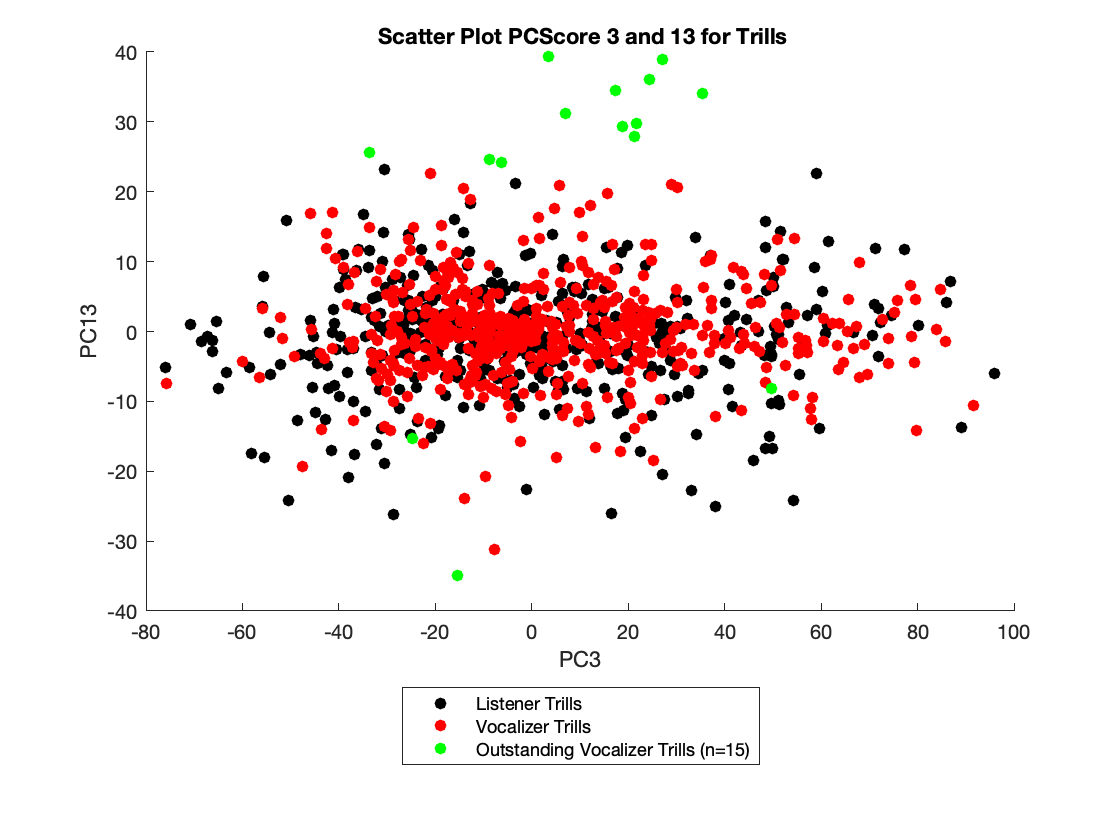

figure()
scatter(Score(OLT_cells,PCSigT(1)),Score(OLT_cells,PCSigT(3)),'ko', 'filled')
hold on


scatter(ScoreOVT(~sum(OutstandingT,2),1),ScoreOVT(~sum(OutstandingT,2),3), 'ro', 'filled')
hold on
scatter(ScoreOVT(logical(sum(OutstandingT,2)),1),ScoreOVT(logical(sum(OutstandingT,2)),3), 'go', 'filled')
hold on


legend({'Listener Trills', 'Vocalizer Trills', sprintf('Outstanding Vocalizer Trills (n=%d)',sum(logical(sum(OutstandingT,2))))}, 'Location', 'southoutside')
xlabel(sprintf('PC%d',PCSigT(1)))
ylabel(sprintf('PC%d',PCSigT(3)))
title(sprintf('{\b Scatter Plot PCScore %d and %d for Trills}',PCSigT(1),PCSigT(3)))
hold off

% What if we use the distribution of Listener cells as the null
% distribution and select cells that are in the 1percentile of that
% distribution?
% Outstanding cells that are in the 1percentile of the Listener
% distribution of values
PvalLim = 0.01;
ScoreOVnT = Score(OVnT_cells,PCSigNT);
ScoreOLnT = Score(OLnT_cells,PCSigNT);
OutstandingNT_pvalue = nan(size(ScoreOVnT,1),length(PCSigNT));
for rr=1:size(ScoreOVnT,1)
    for nPC = 1:length(PCSigNT)
        OutstandingNT_pvalue(rr,nPC) = 1-(sum(sign(LMCoeffVL_nonTrill(PCSigNT(nPC))).*(ScoreOVnT(rr,nPC)-ScoreOLnT(:,nPC))>0)/sum(OLnT_cells));
    end
end
% Now correct that probability for False discovery rate (True proba =
% p*(Num_comparisons-rank))
[~,Ord]=sort([OutstandingNT_pvalue(:,1); OutstandingNT_pvalue(:,2) ; OutstandingNT_pvalue(:,3); OutstandingNT_pvalue(:,4); OutstandingNT_pvalue(:,5)]);
Ord(Ord==length(Ord)) = length(Ord)-1;
Ord1 = Ord(1:size(ScoreOVnT,1));
Ord2 = Ord((1+size(ScoreOVnT,1)) : (2*size(ScoreOVnT,1)));
Ord3 = Ord((1+2*size(ScoreOVnT,1)) : (3*size(ScoreOVnT,1)));
Ord4 = Ord((1+3*size(ScoreOVnT,1)) : (4*size(ScoreOVnT,1)));
Ord5 = Ord((1+4*size(ScoreOVnT,1)) : end);
OutstandingNT_pvalueFDR = [OutstandingNT_pvalue(:,1).*(5*size(ScoreOVnT,1)-Ord1) OutstandingNT_pvalue(:,2).*(5*size(ScoreOVnT,1)-Ord2) OutstandingNT_pvalue(:,3).*(5*size(ScoreOVnT,1)-Ord3) OutstandingNT_pvalue(:,4).*(5*size(ScoreOVnT,1)-Ord4) OutstandingNT_pvalue(:,5).*(5*size(ScoreOVnT,1)-Ord5)];
OutstandingNT = OutstandingNT_pvalueFDR<PvalLim;

% Bonferroni correction is another alternative
%  OutstandingNT = (OutstandingNT_pvalue.*2*size(ScoreOVnT,1))<PvalLim;

figure()
scatter(Score(OLnT_cells,PCSigNT(1)),Score(OLnT_cells,PCSigNT(2)),'ko', 'filled')
hold on


scatter(ScoreOVnT(~sum(OutstandingNT,2),1),ScoreOVnT(~sum(OutstandingNT,2),2), 'ro', 'filled')
hold on
scatter(ScoreOVnT(logical(sum(OutstandingNT,2)),1),ScoreOVnT(logical(sum(OutstandingNT,2)),2), 'go', 'filled')
hold on


legend({'Listener non-Trills', 'Vocalizer non-Trills', sprintf('Outstanding Vocalizer non-Trills (n=%d)',sum(logical(sum(OutstandingNT,2))))}, 'Location', 'southoutside')
xlabel(sprintf('PC%d',PCSigNT(1)))
ylabel(sprintf('PC%d',PCSigNT(2)))
title(sprintf('{\b Scatter Plot PCScore %d and %d for nonTrills}',PCSigNT(1),PCSigNT(2)))
hold off

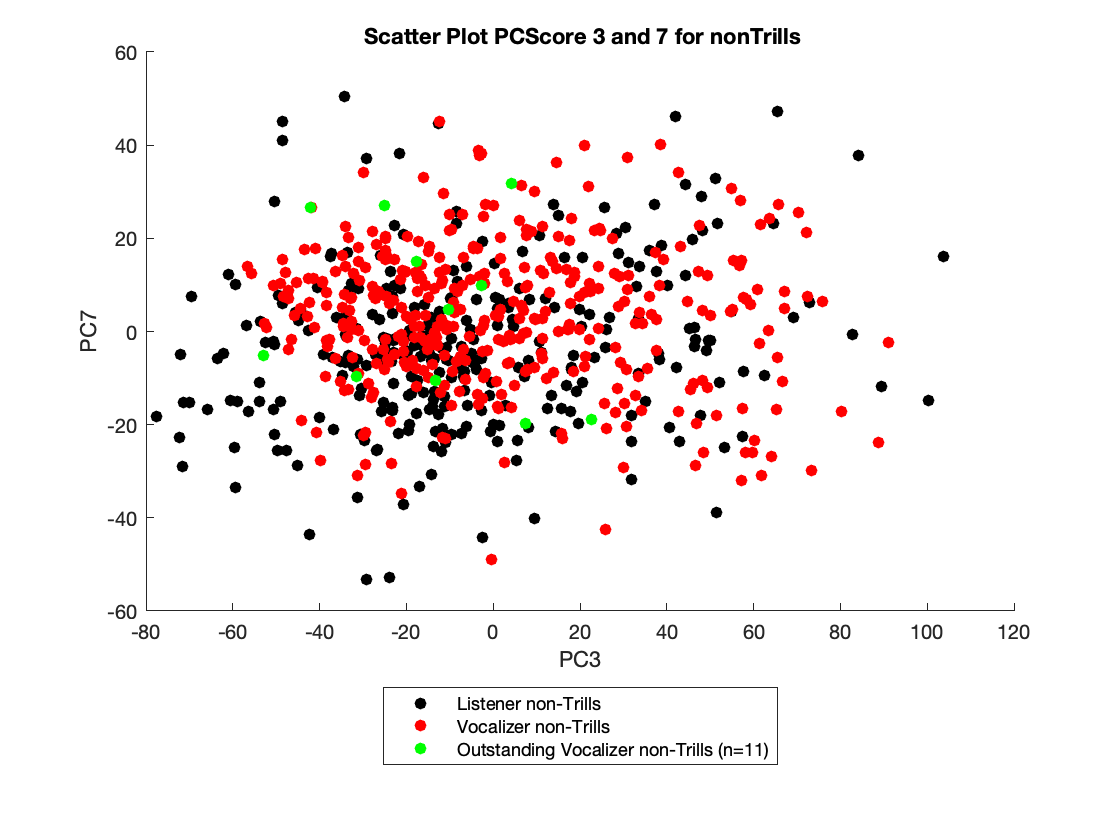


figure()
scatter(Score(OLnT_cells,PCSigNT(1)),Score(OLnT_cells,PCSigNT(3)),'ko', 'filled')
hold on


scatter(ScoreOVnT(~sum(OutstandingNT,2),1),ScoreOVnT(~sum(OutstandingNT,2),3), 'ro', 'filled')
hold on
scatter(ScoreOVnT(logical(sum(OutstandingNT,2)),1),ScoreOVnT(logical(sum(OutstandingNT,2)),3), 'go', 'filled')
hold on


legend({'Listener non-Trills', 'Vocalizer non-Trills', sprintf('Outstanding Vocalizer non-Trills (n=%d)',sum(logical(sum(OutstandingNT,2))))}, 'Location', 'southoutside')
xlabel(sprintf('PC%d',PCSigNT(1)))
ylabel(sprintf('PC%d',PCSigNT(3)))
title(sprintf('{\b Scatter Plot PCScore %d and %d for nonTrills}',PCSigNT(1),PCSigNT(3)))
hold off

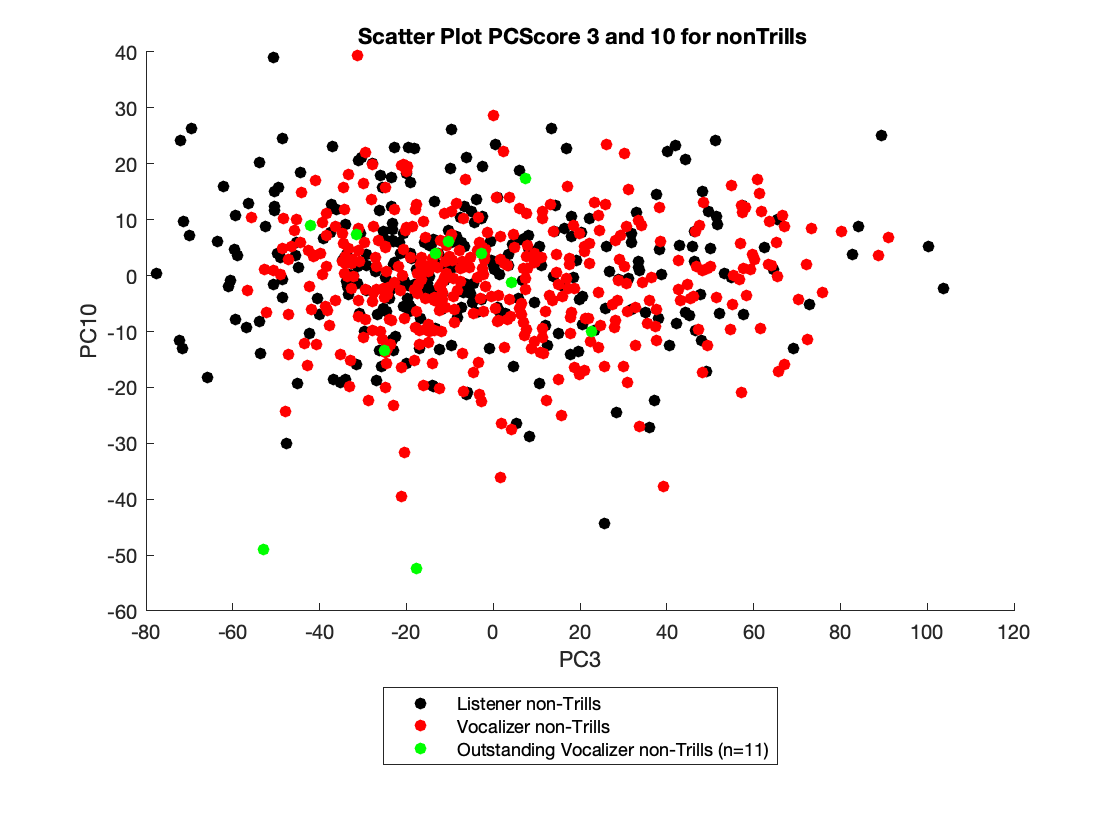

figure()
scatter(Score(OLnT_cells,PCSigNT(1)),Score(OLnT_cells,PCSigNT(4)),'ko', 'filled')
hold on


scatter(ScoreOVnT(~sum(OutstandingNT,2),1),ScoreOVnT(~sum(OutstandingNT,2),4), 'ro', 'filled')
hold on
scatter(ScoreOVnT(logical(sum(OutstandingNT,2)),1),ScoreOVnT(logical(sum(OutstandingNT,2)),4), 'go', 'filled')
hold on


legend({'Listener non-Trills', 'Vocalizer non-Trills', sprintf('Outstanding Vocalizer non-Trills (n=%d)',sum(logical(sum(OutstandingNT,2))))}, 'Location', 'southoutside')
xlabel(sprintf('PC%d',PCSigNT(1)))
ylabel(sprintf('PC%d',PCSigNT(4)))
title(sprintf('{\b Scatter Plot PCScore %d and %d for nonTrills}',PCSigNT(1),PCSigNT(4)))
hold off

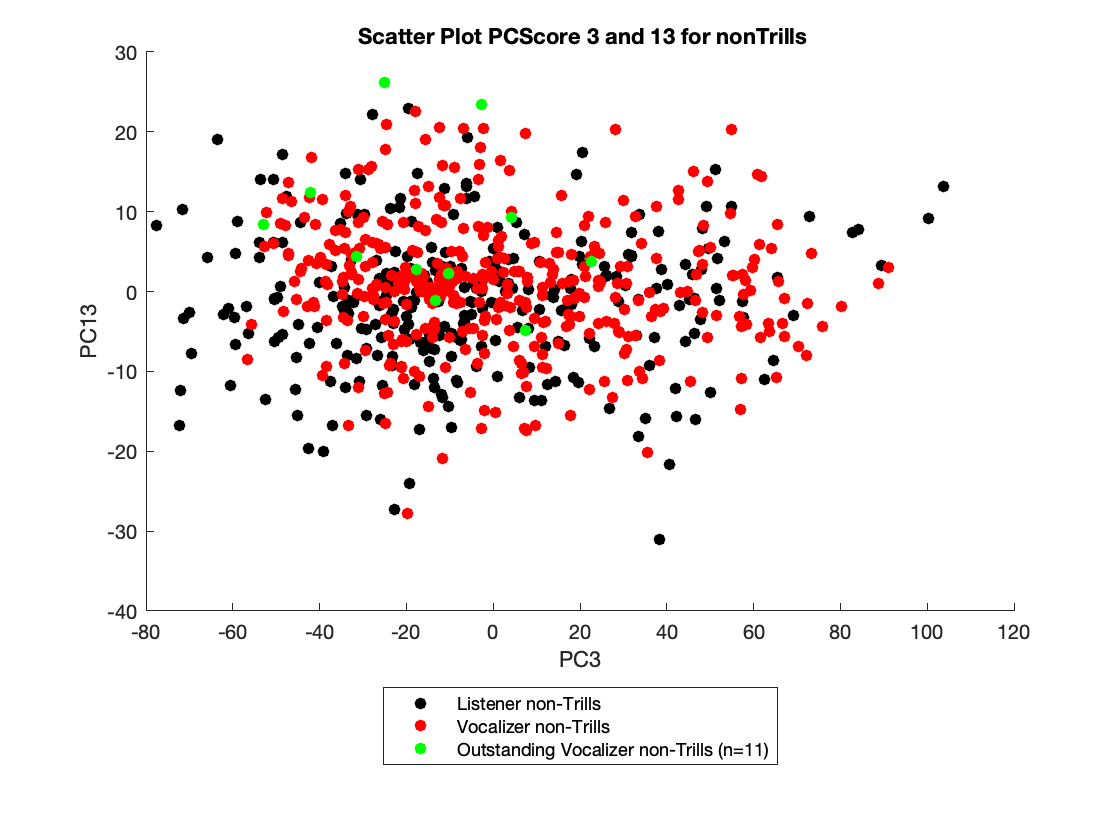


figure()
scatter(Score(OLnT_cells,PCSigNT(1)),Score(OLnT_cells,PCSigNT(5)),'ko', 'filled')
hold on


scatter(ScoreOVnT(~sum(OutstandingNT,2),1),ScoreOVnT(~sum(OutstandingNT,2),5), 'ro', 'filled')
hold on
scatter(ScoreOVnT(logical(sum(OutstandingNT,2)),1),ScoreOVnT(logical(sum(OutstandingNT,2)),5), 'go', 'filled')
hold on


legend({'Listener non-Trills', 'Vocalizer non-Trills', sprintf('Outstanding Vocalizer non-Trills (n=%d)',sum(logical(sum(OutstandingNT,2))))}, 'Location', 'southoutside')
xlabel(sprintf('PC%d',PCSigNT(1)))
ylabel(sprintf('PC%d',PCSigNT(5)))
title(sprintf('{\b Scatter Plot PCScore %d and %d for nonTrills}',PCSigNT(1),PCSigNT(5)))
hold off

% Now create the long logical vector of Outstanding vocalizer responses in
% the same dimensions as score
OutstandingVoc = nan(size(Score,1),1);
OutstandingVoc(OVT_cells) = logical(sum(OutstandingT,2));
OutstandingVoc(OVnT_cells) = logical(sum(OutstandingNT,2));

% Cells are considered having a profile of a vocalizer if for at least one
% of their response (Trills or non-trills), the value of at least one of
% their PC score in the dimension significant in the LM comparing Listener
% and Vocalizer is significantly higher than the distribution of values for
% listener responses with FDR correction

% Indices of Vocalizer cells in Score that have Tr or nTr or both
CellIDV = find(OperantVocalizerCells01);
VCells = nan(length(CellIDV),3); % Col1: Boolean Significantly larger PC than Listener cells for at least one call type; Col2: Number of call types for which PC could be calculated; Col3: Call types neural activity significantly different for V vs L (2: both, 1: Trills, 0: non-trills)
for cc=1:length(CellIDV)
    CellIndices = find(CellID == CellIDV(cc));
    if length(CellIndices)==2
        OutstandingVoc2 = OutstandingVoc(CellIndices);
        VCells(cc,1) = logical(prod(OutstandingVoc2));
        VCells(cc,2) = 2;
        if VCells(cc,1)==0 && OutstandingVoc2(1) %Large distance for Trills Significance for Trills only 
            VCells(cc,1) = 1;
            VCells(cc,3) = 1;
        elseif VCells(cc,1)==0 && OutstandingVoc2(2)  %Large distance for non-Trills Significance for non-Trills only 
            VCells(cc,1) = 1;
            VCells(cc,3) = 0;
        elseif VCells(cc,1)==1
            VCells(cc,3) = 2;
        end

    elseif (length(CellIndices)==1) && CellIndices(1)<=sum(~NanTr) % Distance for Trill only
        VCells(cc,1) = OutstandingVoc(CellIndices);
        VCells(cc,2) = 1;
        if VCells(cc,1)
            VCells(cc,3) = 1;
        end
    elseif (length(CellIndices)==1) && CellIndices(1)>sum(~NanTr) % Distance for Non-Trill only
        VCells(cc,1) = OutstandingVoc(CellIndices);
        VCells(cc,2) = 1;
        if VCells(cc,1)
            VCells(cc,3) = 0;
        end
    else
        keyboard % there is an issue!
    end

end


% Cells that are either SMU or SSU
ListCellsG = ListCells(GoodCellIndices);
% select cells that are from vocalizer of either Trills or non-trills or both during operant and that have a minimum average rate over all voc of 0.1Hz
ListCellsGV = ListCellsG(logical(OperantVocalizer.*BaorTr_0ind));
% These are cells with the out of the chart values for components that
% discriminate Listener from vocalizer
ListCellsGV(logical(VCells(:,1)))

ans = 26×1 cell array
    {'/Volumes/JulieE8T/LMCResults/59834_20190605_SSM_1-183.mat'}
    {'/Volumes/JulieE8T/LMCResults/59834_20190605_SSM_1-97.mat' }
    {'/Volumes/JulieE8T/LMCResults/59834_20190611_SSS_3-137.mat'}
    {'/Volumes/JulieE8T/LMCResults/59834_20190613_SSS_3-127.mat'}
    {'/Volumes/JulieE8T/LMCResults/59834_20190613_SSM_3-147.mat'}
    {'/Volumes/JulieE8T/LMCResults/59834_20190618_SSM_2-121.mat'}
    {'/Volumes/JulieE8T/LMCResults/59834_20190619_SSS_4-216.mat'}
    {'/Volumes/JulieE8T/LMCResults/59834_20190620_SSM_1-87.mat' }
    {'/Volumes/JulieE8T/LMCResults/59834_20190622_SSM_3-162.mat'}
    {'/Volumes/JulieE8T/LMCResults/59834_20190623_SSM_1-94.mat' }
    {'/Volumes/JulieE8T/LMCResults/59834_20190626_SSM_1-233.mat'}
    {'/Volumes/JulieE8T/LMCResults/59834_20190627_SSS_4-292.mat'}
    {'/Volumes/JulieE8T/LMCResults/59834_20190628_SSS_3-178.mat'}
    {'/Volumes/JulieE8T/LMCResults/59834_20190629_SSM_1-115.mat'}
    {'/Volumes/JulieE8T/LMCResults/59834_20190708_SSM_

fprintf(1, 'There are %d/%d cells from vocalizer bats with out of the chart values for components that dicriminate Listeners from vocalizers', sum(VCells(:,1)), size(VCells,1))

There are 26/596 cells from vocalizer bats with out of the chart values for components that dicriminate Listeners from vocalizers

ListCellsVocPCAComponent = ListCellsGV(logical(VCells(:,1)));
save(fullfile(Path2AllData,'population_PCA_GLM_data.mat'), 'ListCellsVocPCAComponent','VCells', '-append')

% For the vocalizer cells with motor components, get values of Information on motor and auditory coherence in Free
% session and motor coherence in operant, along with the time resolution of
% these cells. I need to find what would be the optimal size of the
% Gaussian for the next step (PCA on time varying spike rate of each vocalization for
% each cell)
% Values of MI COherence with Vocal production in Operant
HDPath = '/Volumes/JulieE8T/LMCResults/';
MC = load(fullfile(HDPath,sprintf('MotorCoherence_%s_%s.mat', 'amp', 'Operant')));
% Gather data on Info
InfoMotorOpGVCells = nan(sum(VCells(:,1)),3);% first column value of info, 2nd pRandSpikePer, 3rd pRandVoc
DelayResolutionMotorOpGVCells = nan(sum(VCells(:,1)),3); % first column delay in ms, 2nd column resolution
NanCount = [];
for cc=1:length(MC.CellsPath)
    Ind=find(contains(ListCellsVocPCAComponent, MC.CellsPath(cc).name));
    if ~isempty(Ind)
        InfoMotorOpGVCells(Ind,1) = MC.Info(cc);
        if isnan(MC.Info(cc))
            NanCount = [NanCount Ind];
        end
        InfoMotorOpGVCells(Ind,2) = MC.Info_pRandSpikePerm(cc);
        InfoMotorOpGVCells(Ind,3) = MC.Info_pRandVoc(cc);
        DelayResolutionMotorOpGVCells(Ind,1) = MC.CoherencyT_DelayAtzero(cc);
        DelayResolutionMotorOpGVCells(Ind,2) = 1000./(2*MC.CoherenceWeightedFreq(cc));
    end
end
fprintf(1,'Could not find any value of Motor information in Operant for %d cells', length(NanCount))

Could not find any value of Motor information in Operant for 0 cells

NanCount


NanCount =

     []



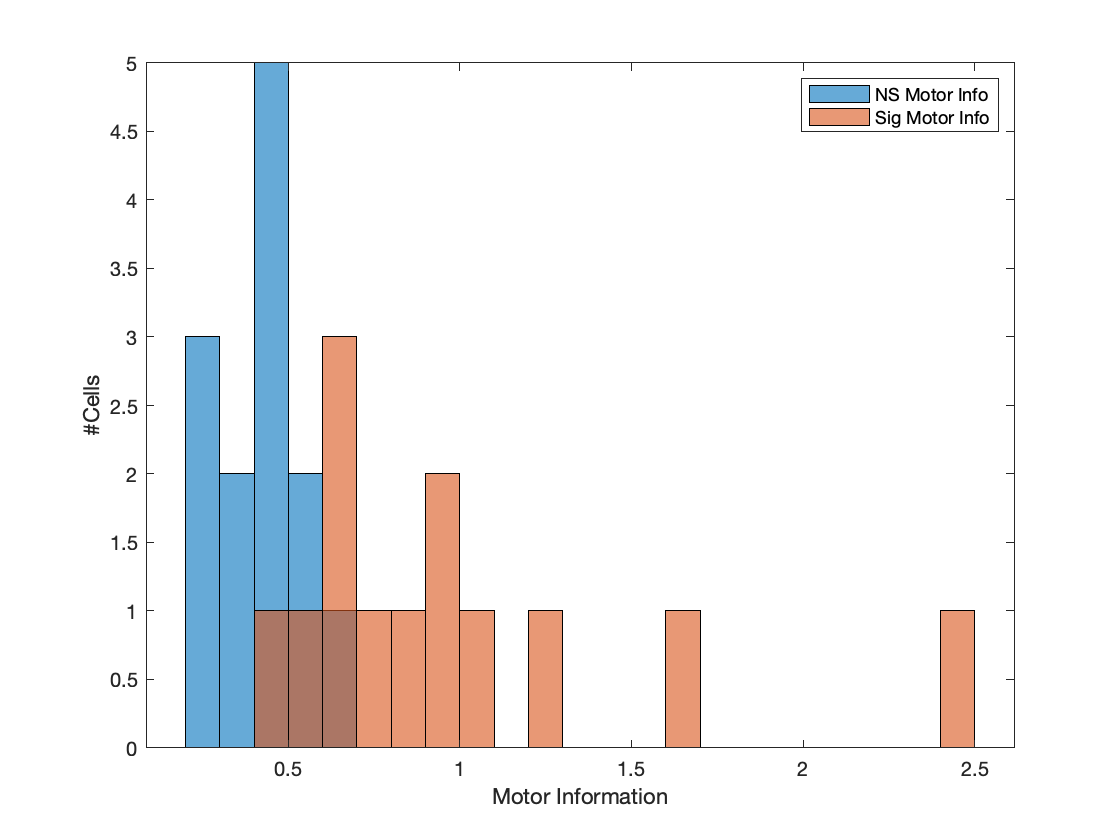

% Plot the values of coherence Information
ColPC = get(groot, 'DefaultAxesColorOrder');
SigMotorCells = (InfoMotorOpGVCells(:,2)<0.01);
SigGestureCells = (InfoMotorOpGVCells(:,3)<0.01);
figure()
histogram(InfoMotorOpGVCells(~SigMotorCells,1), 'BinWidth',0.1)
hold on
histogram(InfoMotorOpGVCells(SigMotorCells,1), 'BinWidth',0.1)
legend('NS Motor Info', 'Sig Motor Info')
ylabel('#Cells')
xlabel('Motor Information')
hold off

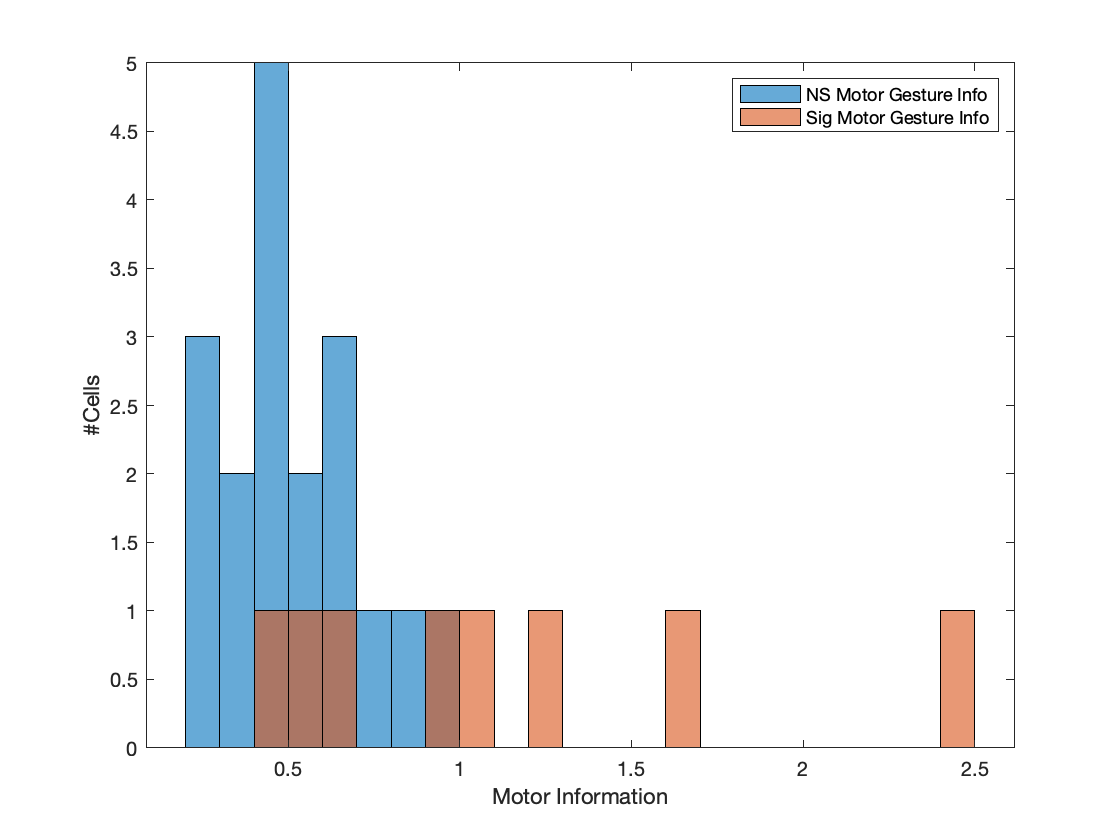


figure()
histogram(InfoMotorOpGVCells(~SigGestureCells,1), 'BinWidth',0.1)
hold on
histogram(InfoMotorOpGVCells(SigGestureCells,1), 'BinWidth',0.1)
legend('NS Motor Gesture Info', 'Sig Motor Gesture Info')
ylabel('#Cells')
xlabel('Motor Information')
hold off

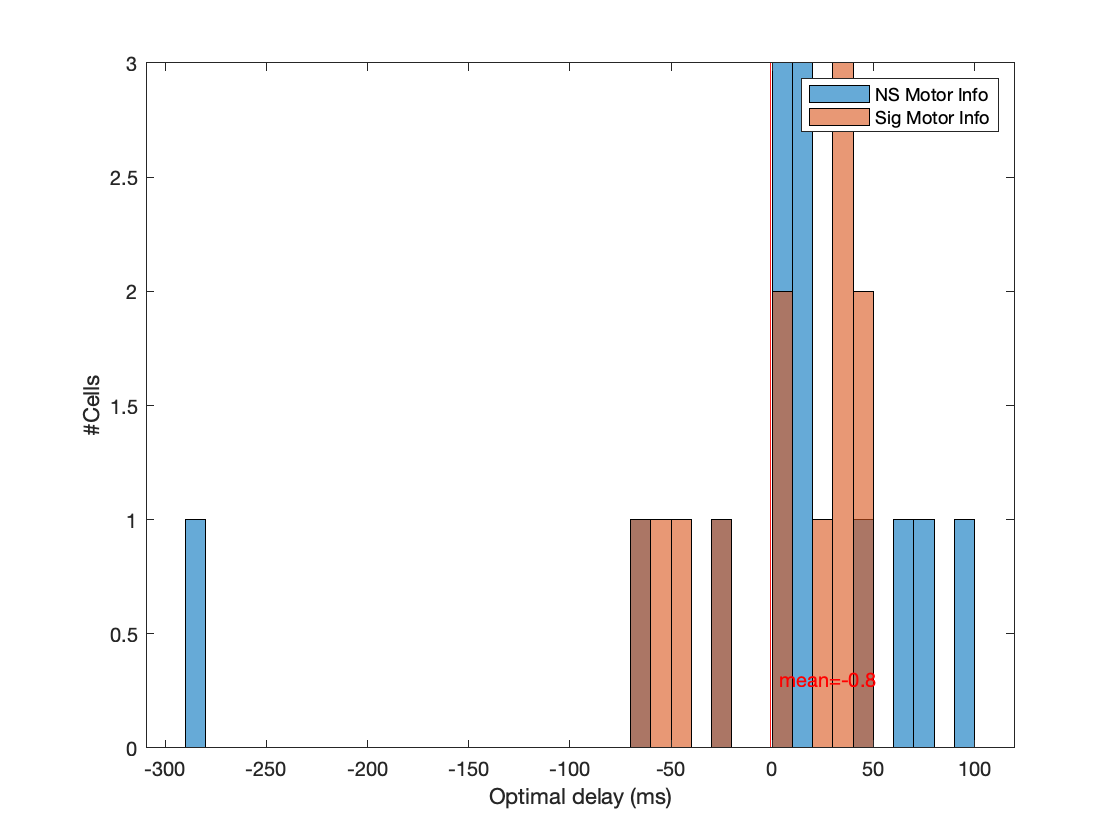

% Plot the values of coherence delay
ColPC = get(groot, 'DefaultAxesColorOrder');
SigMotorCells = (InfoMotorOpGVCells(:,2)<0.01);
SigGestureCells = (InfoMotorOpGVCells(:,3)<0.01);
figure()
histogram(DelayResolutionMotorOpGVCells(~SigMotorCells,1), 'BinWidth',10)
hold on
histogram(DelayResolutionMotorOpGVCells(SigMotorCells,1), 'BinWidth',10)
legend('NS Motor Info', 'Sig Motor Info')
legend('AutoUpdate', 'Off') 
vline(mean(DelayResolutionMotorOpGVCells(:,1), 'omitnan'), 'r-',sprintf('mean=%.1f',mean(DelayResolutionMotorOpGVCells(:,1),'omitnan') ))
ylabel('#Cells')
xlabel('Optimal delay (ms)')
hold off

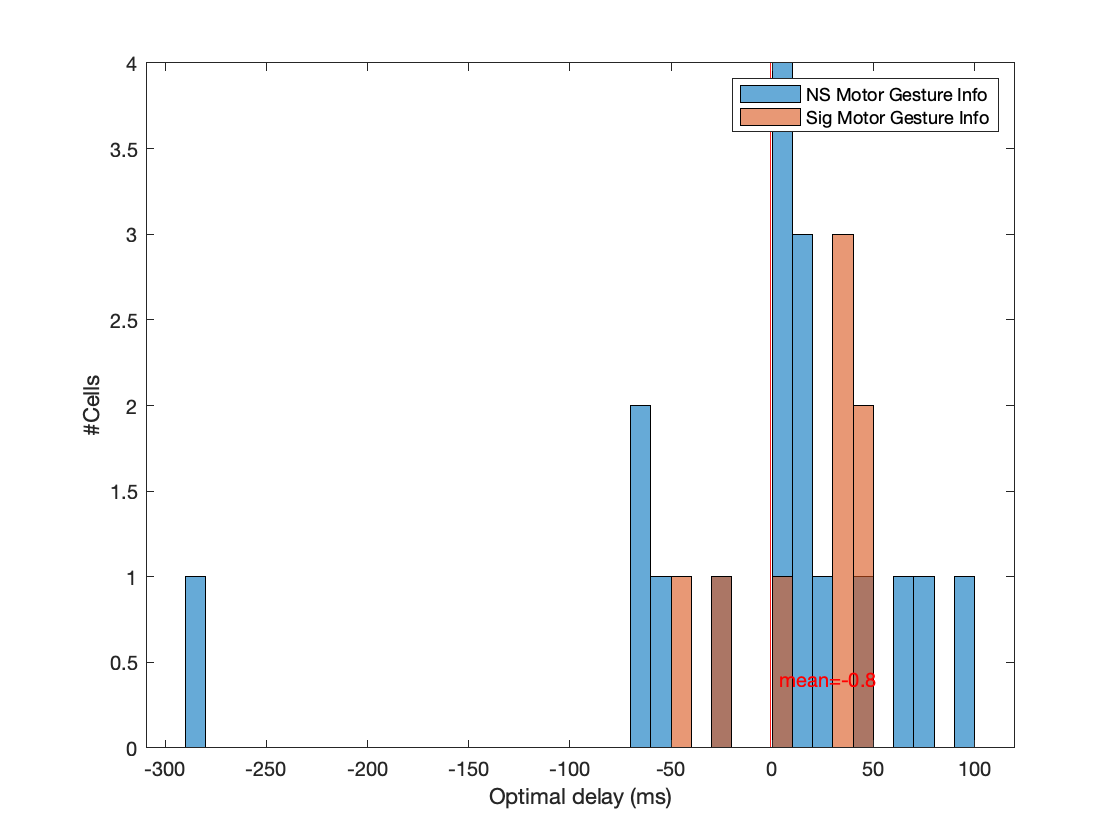


figure()
histogram(DelayResolutionMotorOpGVCells(~SigGestureCells,1), 'BinWidth',10)
hold on
histogram(DelayResolutionMotorOpGVCells(SigGestureCells,1), 'BinWidth',10)
legend('NS Motor Gesture Info', 'Sig Motor Gesture Info')
legend('AutoUpdate', 'Off')
vline(mean(DelayResolutionMotorOpGVCells(:,1),'omitnan'), 'r-',sprintf('mean=%.1f',mean(DelayResolutionMotorOpGVCells(:,1),'omitnan') ))
ylabel('#Cells')
xlabel('Optimal delay (ms)')
hold off

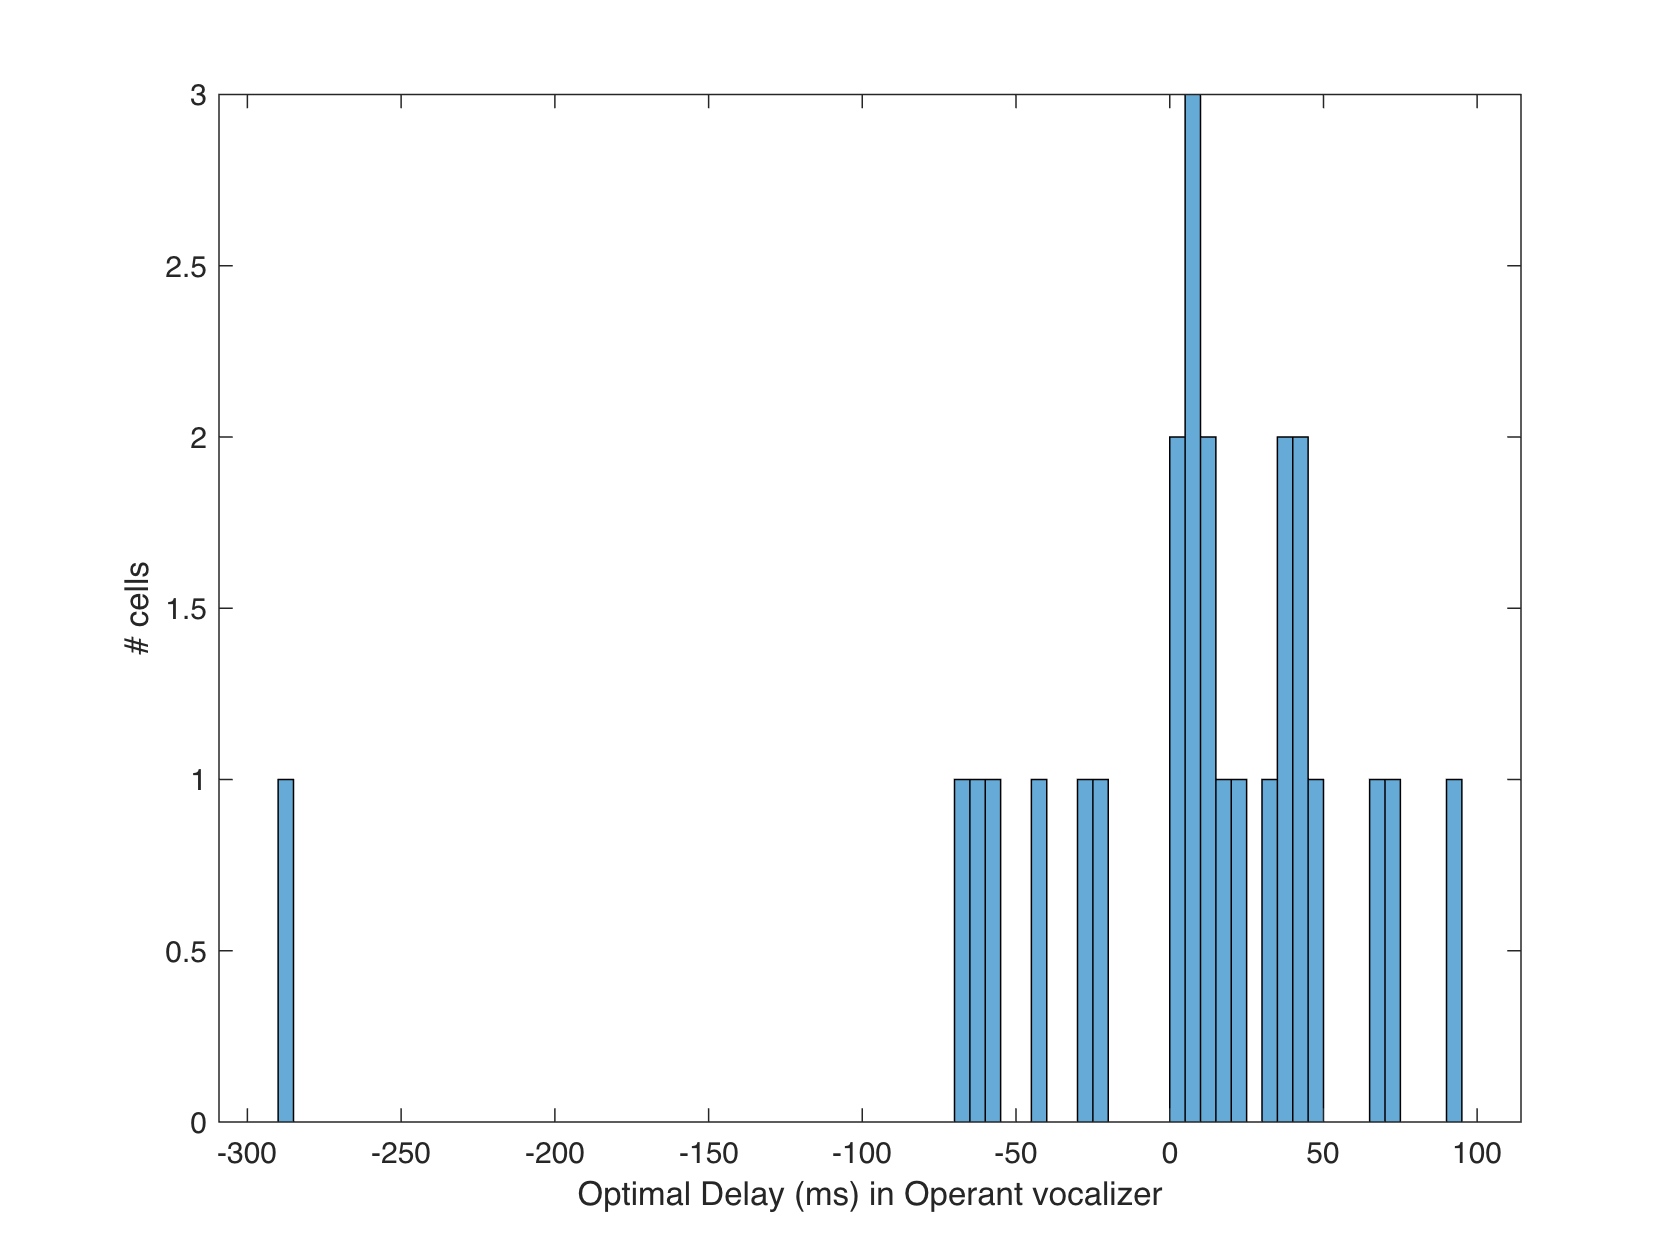

% plot the value of optimal Delay and Optimal resolution for these cells
% during Operant
histogram(DelayResolutionMotorOpGVCells(:,1), 'BinWidth',5)
hold on
vline(mean(DelayResolutionMotorOpGVCells(:,1)), 'r-',sprintf('mean=%.1f',mean(DelayResolutionMotorOpGVCells(:,1)) ))
hold off
ylabel('# cells')
xlabel('Optimal Delay (ms) in Operant vocalizer')

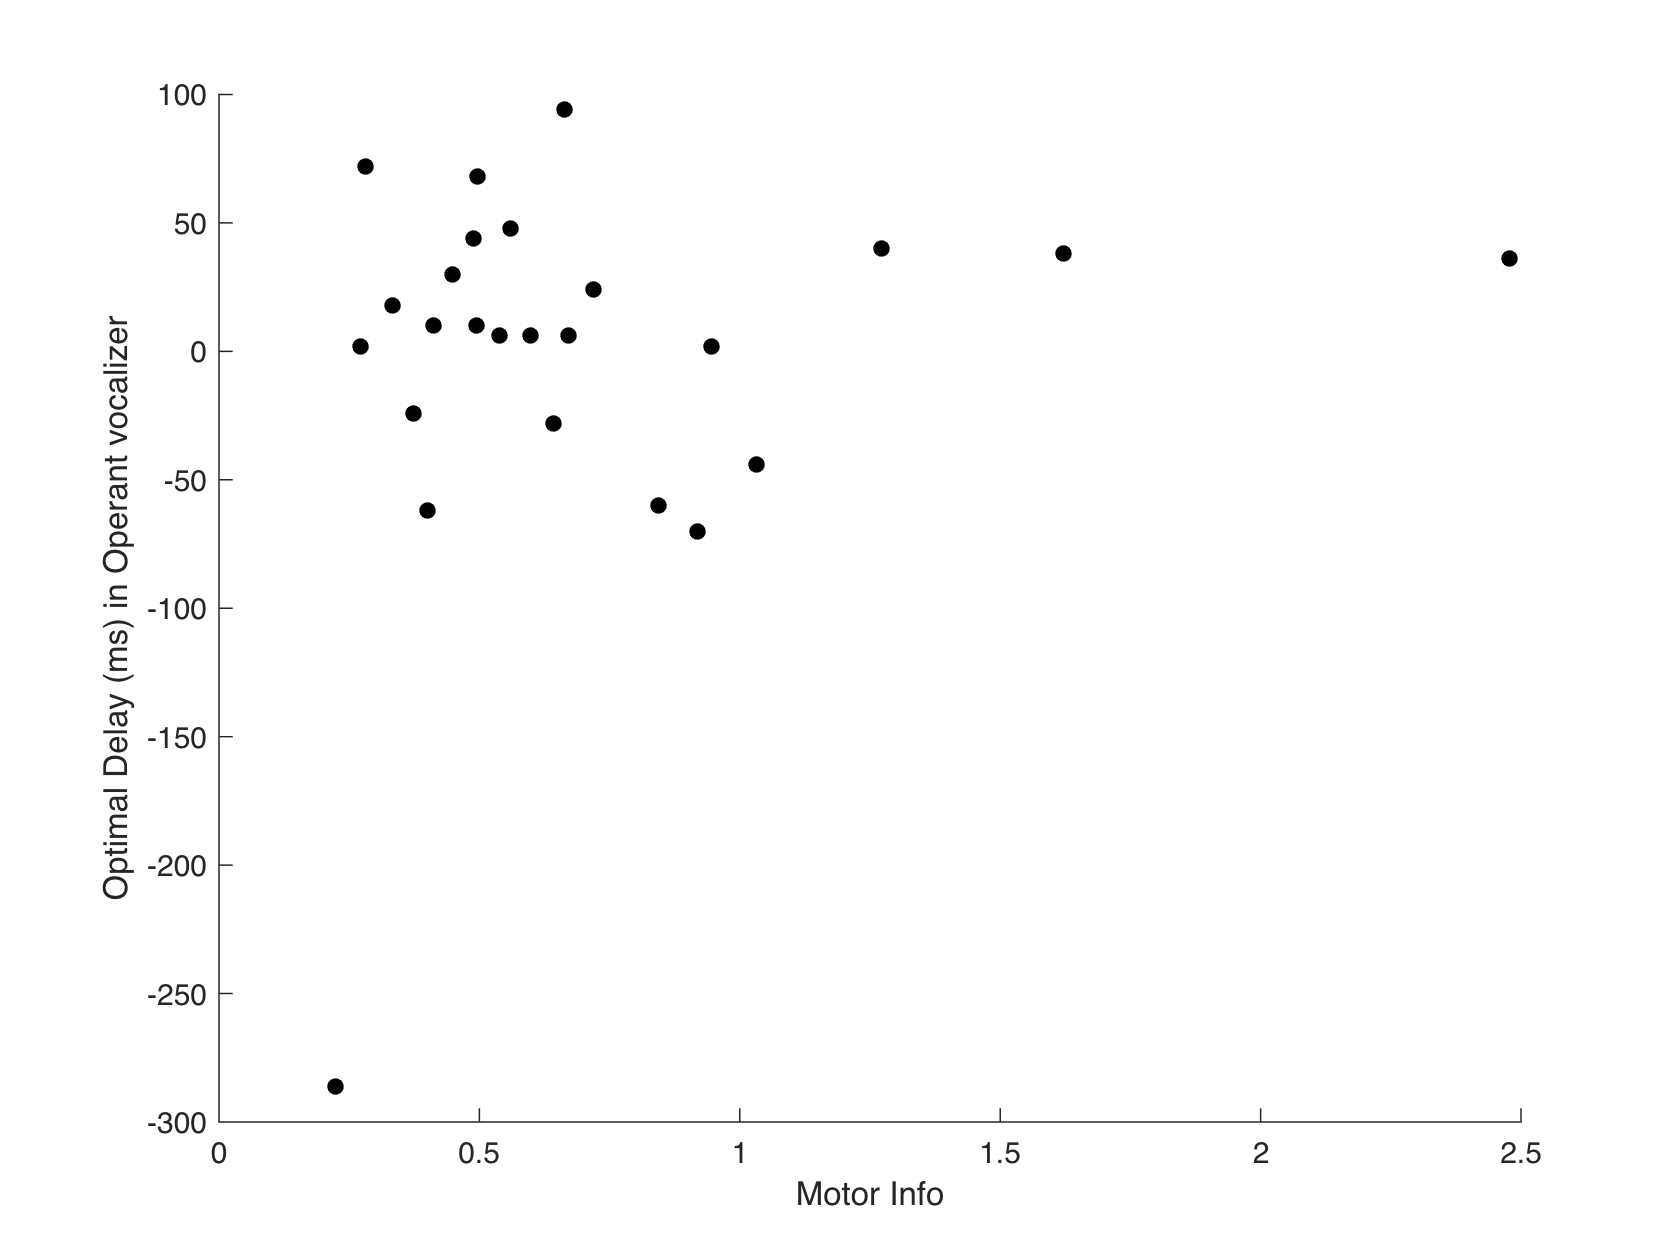

figure()
scatter(InfoMotorOpGVCells(:,1),DelayResolutionMotorOpGVCells(:,1), 30, 'k', 'filled')
xlabel('Motor Info')
ylabel('Optimal Delay (ms) in Operant vocalizer')

fprintf(1,'Minimum optimal delay = %d ms', min(DelayResolutionMotorOpGVCells(:,1)))

Minimum optimal delay = -286 ms

histogram(DelayResolutionMotorOpGVCells(:,2), 'BinWidth',1)
hold on
vline(mean(DelayResolutionMotorOpGVCells(:,2)), 'r-',sprintf('mean=%.1f',mean(DelayResolutionMotorOpGVCells(:,2)) ))
fprintf(1,'Mean optimal resolution = %.2f ms', mean(DelayResolutionMotorOpGVCells(:,2)))

Mean optimal resolution = 9.59 ms

hold on
vline(median(DelayResolutionMotorOpGVCells(:,2)), 'b-',sprintf('median=%.1f',median(DelayResolutionMotorOpGVCells(:,2)) ))
fprintf(1,'Median optimal resolution = %.2f ms', median(DelayResolutionMotorOpGVCells(:,2)))

Median optimal resolution = 7.81 ms

hold on
vline(quantile(DelayResolutionMotorOpGVCells(:,2), 0.25), 'g-',sprintf('Q25=%.1f',quantile(DelayResolutionMotorOpGVCells(:,2),0.25)))
fprintf(1,'75%% of cells have optimal resolution > %.2f ms', quantile(DelayResolutionMotorOpGVCells(:,2),0.25))

75% of cells have optimal resolution > 5.42 ms

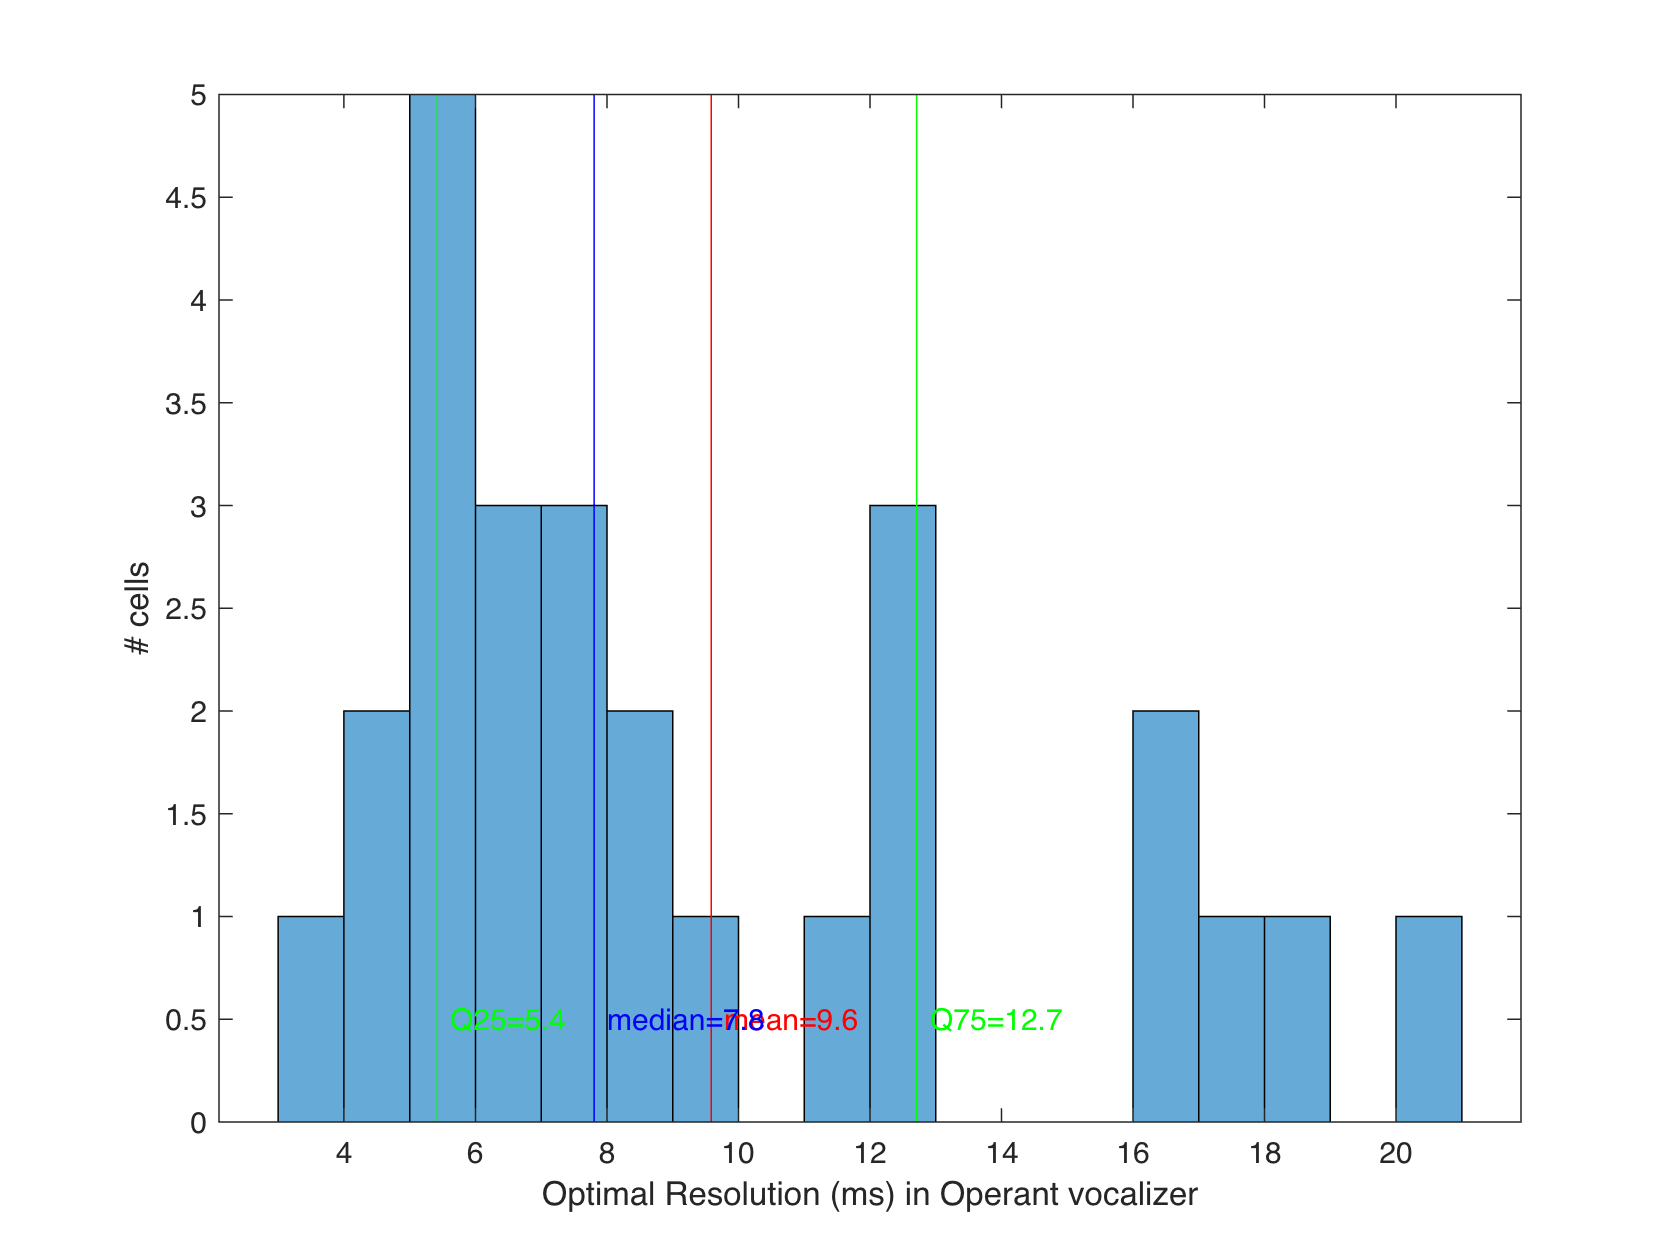

hold on
vline(quantile(DelayResolutionMotorOpGVCells(:,2), 0.75), 'g-',sprintf('Q75=%.1f',quantile(DelayResolutionMotorOpGVCells(:,2),0.75)))
ylabel('# cells')
xlabel('Optimal Resolution (ms) in Operant vocalizer')
hold off

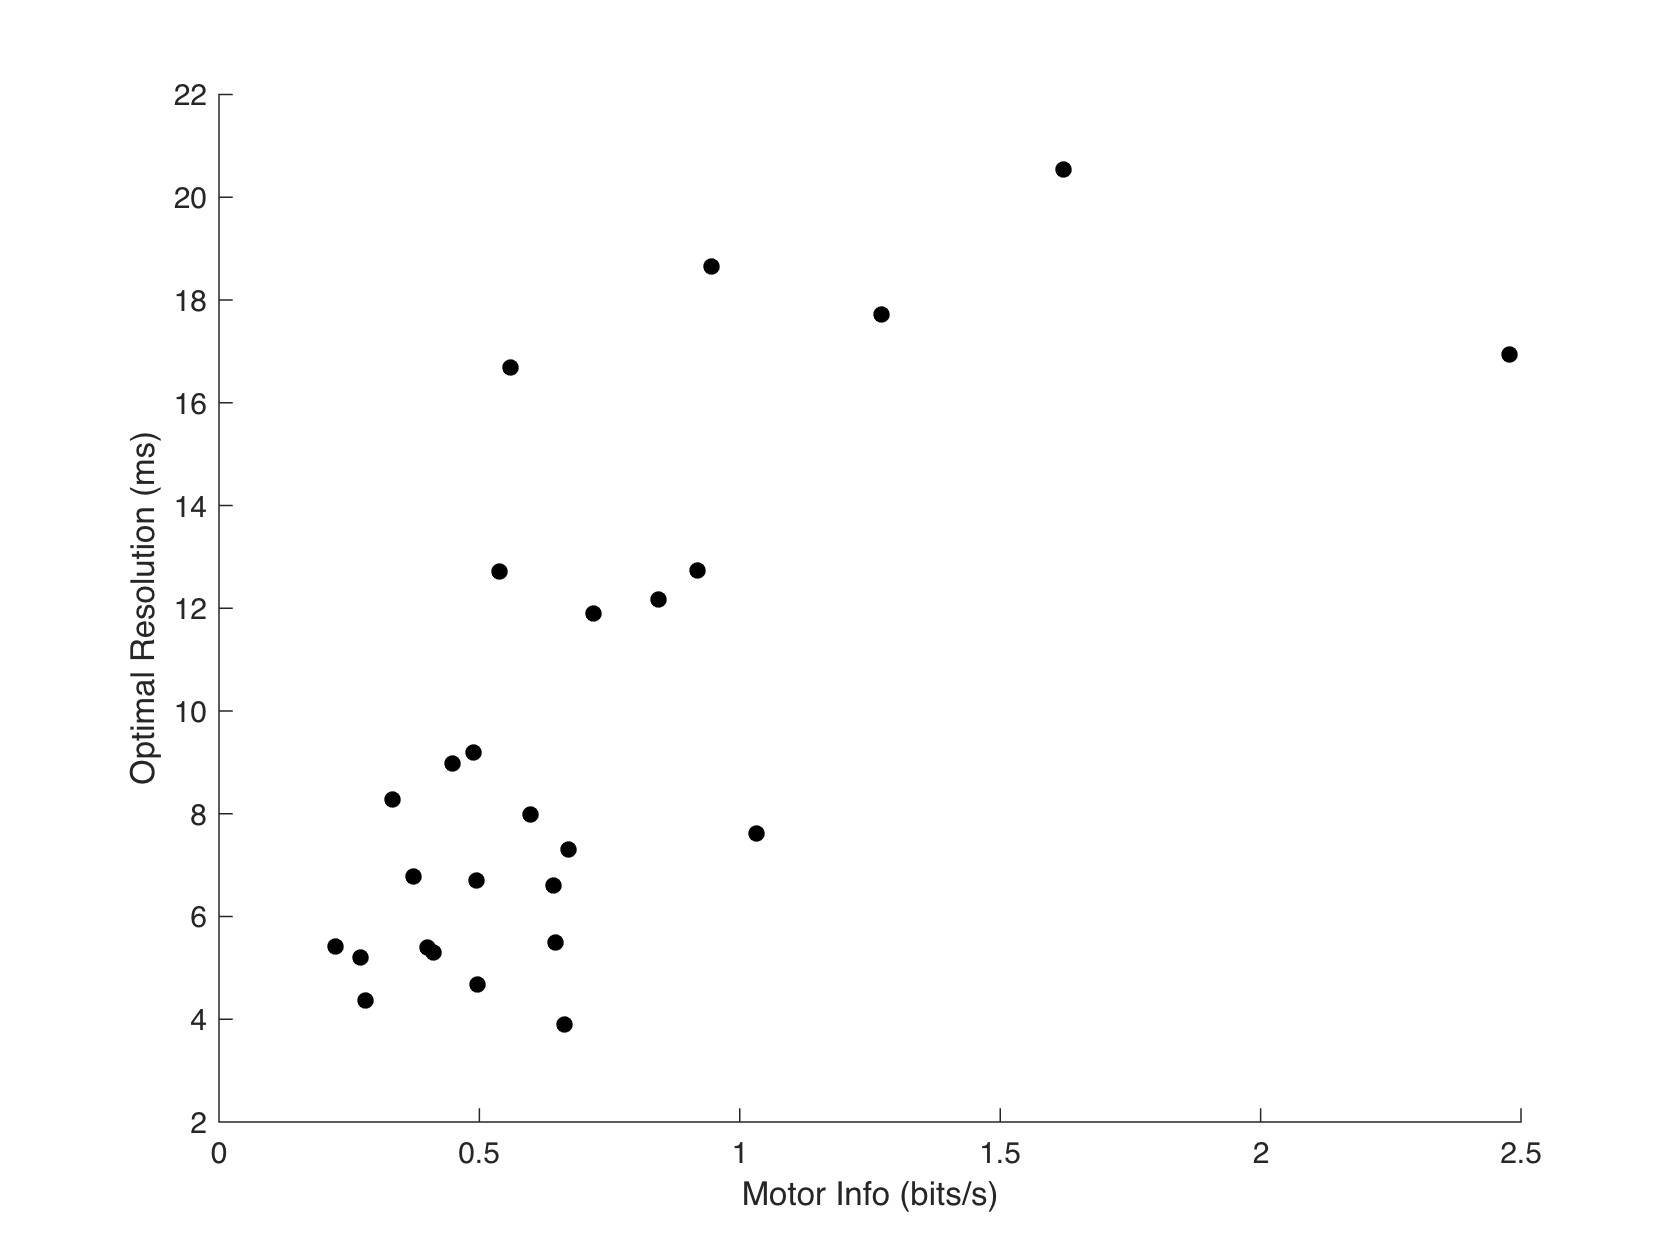

scatter(InfoMotorOpGVCells(:,1),DelayResolutionMotorOpGVCells(:,2), 30, 'k', 'filled')
xlabel('Motor Info (bits/s)')
ylabel('Optimal Resolution (ms)')